# Unveiling iPD Modulation

[*Matthias Wolff*](https://www.b-tu.de/en/fg-kommunikationstechnik/team/staff/prof-dr-ing-habil-matthias-wolff)

[BTU Cottbus-Senftenberg](https://www.b-tu.de/en/), [Chair of Communications Engineering](https://www.b-tu.de/en/fg-kommunikationstechnik)

% Settings
pfx  = 'recordings/phaseModulationAnalysis/';

## 1   Problem Statement

From the VZ-1 manual I got the (wrong) impression that "phase modulation" of the two oscillator signals of one line would work something like this:

    
$$y(t) = x_2\big(2\pi f_{02}t + h\pi x_1(2\pi f_{01}t)\big),$$


i.e., what I would consider a "normal" phase modulation. In the formula, $f_{01}$ and $f_{02}$ denote the note frequencies of two oscillators---say `M1` and `M2`---, $x_1(t)$ and $x_2(t)$ their output signals, $h$ the modulation index, i.e., the modulation "depth", and $y(t)$ the phase modulated signal. I further assume that $x_1$ and $x_2$ are periodic with a cycle length of $2\pi$ and take values $-1\leq x\leq 1$.

Some little measurements phase modulating two sine signals of the same frequency 

     $x_{SINE}(t) = \sin(2\pi f_0t-\pi)$      --- the SINE oscillator signal of the VZ comes with a phase offset of $-\pi$ ---

showed that it *does not* work this way:

- The note frequency $f_{01}$ of $x_1(t)$ does not seem to matter at all. Detuning $x_1$ does not have any influence on the phase-modulated signal $y(t)$.

- This phase modulated-line signal $y(t)$ itself looks other than expected.

- The amplitude of the modulated signal seems to vary with the modulation index $h$ (which should not happen with any kind of phase modulation).

So what *does* VZ's iPDM do?

## 2   Reverse-Engineering iPDM

### 2.1   Test Recordings of VZ-1

To puzzle out what is going on, I did some some test recordings of VZ-1. I proceeded as follows:

- Set the master tune in `Menu 3-00` to `TUNE(A4)=440.0`(Hz),

- Initialize a new voice `Menu 1-00`...`Menu 1-18`: [Copy/Initialize]+[YES], for all modules `M1`...`M8` where applicable,

- Deactivate all modules except `M1` and `M2`,

- Set `M1` and `M2` to fix pitch: `Menu 1-02`, `PITCH FIX=ON (x1)`,` OCT=02`,` NOTE=00`,` FINE=09`,

- Set `INT LINE=PHASE` for modules `M1` and `M2` in `Menu 0-00` (except recording #1),

- Set `FORM=<xxx>` for modules `M1` and `M2` in `Menu 0-01` according to table below,

- Set modulation index in `Menu 1-09`, `ENV DEPTH=<nn>` according to table below,

- Record the phase modulated output signal at a sampling frequency of 48 kHz (a cycle will be 1024 samples long with the fix pitch settings above),

- Manually label the zero-crossings of a falling edge in all recordings (approx. 10 cycles into the wave), and

- Automatically cut out one waveform cycle, i.e., 1024 samples, starting at the labeled position.

Overview of recordings and settings:

%  ---------------------------------------------------------------------------------------------
%  No.   M1    M2    M1 ENV DEPTH  File in "<vVZ>/waves/recordings/phase modulation measurement"
%  ---------------------------------------------------------------------------------------------
%   1    SINE  OFF   n/a           "M1=SINE, 46.875 Hz.wav"
%   2    SINE  SINE  00            "M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=00"
%   3    SINE  SINE  09            "M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=09"
%   4    SINE  SINE  19            "M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=19"
%   5    SINE  SINE  29            "M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=29"
%   6    SINE  SINE  39            "M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=39"
%   7    SINE  SINE  49            "M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=49"
%   8    SINE  SINE  59            "M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=59"
%   9    SINE  SINE  69            "M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=69"
%  10    SINE  SINE  79            "M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=79"
%  11    SINE  SINE  89            "M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=89"
%  12    SINE  SINE  99            "M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=99"
%  13    SAW1  SINE  29            "M1=SAW1, M2=SINE, 46.875 Hz, ENV DEPTH=29"
%  14    SAW2  SINE  29            "M1=SAW2, M2=SINE, 46.875 Hz, ENV DEPTH=29"
%  15    SAW3  SINE  29            "M1=SAW3, M2=SINE, 46.875 Hz, ENV DEPTH=29"
%  16    SAW4  SINE  29            "M1=SAW4, M2=SINE, 46.875 Hz, ENV DEPTH=29"
%  17    SAW5  SINE  29            "M1=SAW5, M2=SINE, 46.875 Hz, ENV DEPTH=29"
%  ---------------------------------------------------------------------------------------------

### 2.2   `SINE(SINE)` Phase Modulation

fprintf(['_____________________________________________________________________\n' ...
  '2.2 SINE(SINE) Phase Modulation']);

_____________________________________________________________________
2.2 SINE(SINE) Phase Modulation

First, we examine recordings 1 through 12, i.e., a sine modulating a sine with varying modulation depths. In the following I assume that all signals are periodic with a cycle length of $2\pi$. I denote by $x_1$ and $x_2$ the output signals of oscillators `M1` and `M2`, respectively, and by $y$ the modulated line output signal.

If the VZ does a phase modulation at all, the line output signal should be

    $y(\varphi) = x_2\big(\varphi + \varphi_{x1}(\varphi)\big)$,

    $\to$ continuous time: $\varphi = 2\pi f_0t$    with $f_0$: note frequency --- as only $f_{02}$ matters, I will just write $f_0$ ---

    $\to$ discrete time     : $\varphi=2\pi\frac{k}{K}$   with $K$: cycle length, again of both oscillators, in samples,

and I would expect the phase signal $\varphi_{x1}$ to somehow depend on the `M1` oscillator sigal $x_1$. VZ uses inverted sine signals

    $x_{\text{SINE}}(\varphi) = \sin(\varphi-\pi)$,

    $\to$ continuous time: $x_{\text{SINE}}(t) = \sin(2\pi f_0t-\pi)$,

    $\to$ discrete time     : $x_{\text{SINE}}(k) = \sin\left(2\pi\frac{k}{K}-\pi\right)$.

As we modulate a VZ-style sine signal, I can rewrite the phase-modulated signal as

    $y(\varphi) = a\,\sin\big(\varphi-\pi+\varphi_{x1}(\varphi)\big)$,

   $\to$  continuous time: $y(t) = a\,\sin\big(2\pi f_0t-\pi+\varphi_{x1}(2\pi f_0t)\big)$,

   $\to$  discrete time     : $y(k) = a\,\sin\left(2\pi\frac{k}{K}-\pi+\varphi_{x1}\left(2\pi\frac{k}{K}\right)\right)
$.

I introduced a gain factor $a$ because the amplitude of my recorded signals is not $1$.  For the digital recordings, the settings above guarantee a cycle length of $K=1024$.

Given recordings of $y(\varphi)$ and the model $x_2(\varphi)=\sin(\varphi-\pi)$ of the "carrier" signal, I can numerically solve for $\varphi_{x1}(\varphi)$. Note that the solution is not unique. We expect two solutions in the interval $0\leq \varphi_{x1}(\varphi)<2\pi$. Phase unwrapping adds a multitude of further solutions. I will draw some of them in a scatter plot for each recording.

fprintf(['_____________________________________________________________________\n' ...
 'Analyzing phase modulation']);

_____________________________________________________________________
Analyzing phase modulation

Let's first try an unmodulated sine wave (recording #1):

rlst  = vVZtools.listRecordings([pfx '.*M1=SINE, M2=OFF.*']);
rec   = loadRecordings(rlst,1024); fprintf('- Cycle data\n'); disp(rec);

M1=SINE, M2=OFF, 46.875 Hz
vVZtools.loadRecording(rid="recordings/phaseModulationAnalysis/M1=SINE, M2=OFF, 46.875 Hz")
- Read wave file "../waves/recordings/phaseModulationAnalysis/M1=SINE, M2=OFF, 46.875 Hz.wav"
  - OK, 79260 samples
- Read annotation file "../labels/recordings/phaseModulationAnalysis/M1=SINE, M2=OFF, 46.875 Hz.par"
  - Read properties
    - OK, 9 properties
  - Read pitch marks
    - OK, 44 pitch marks
- Cycle data
    name: 'M1=SINE, M2=OFF, 46.875 Hz'
    wave: [1024×1 double]
      k0: 25533
       K: 1024
       a: 0.3150
       h: 0.9900



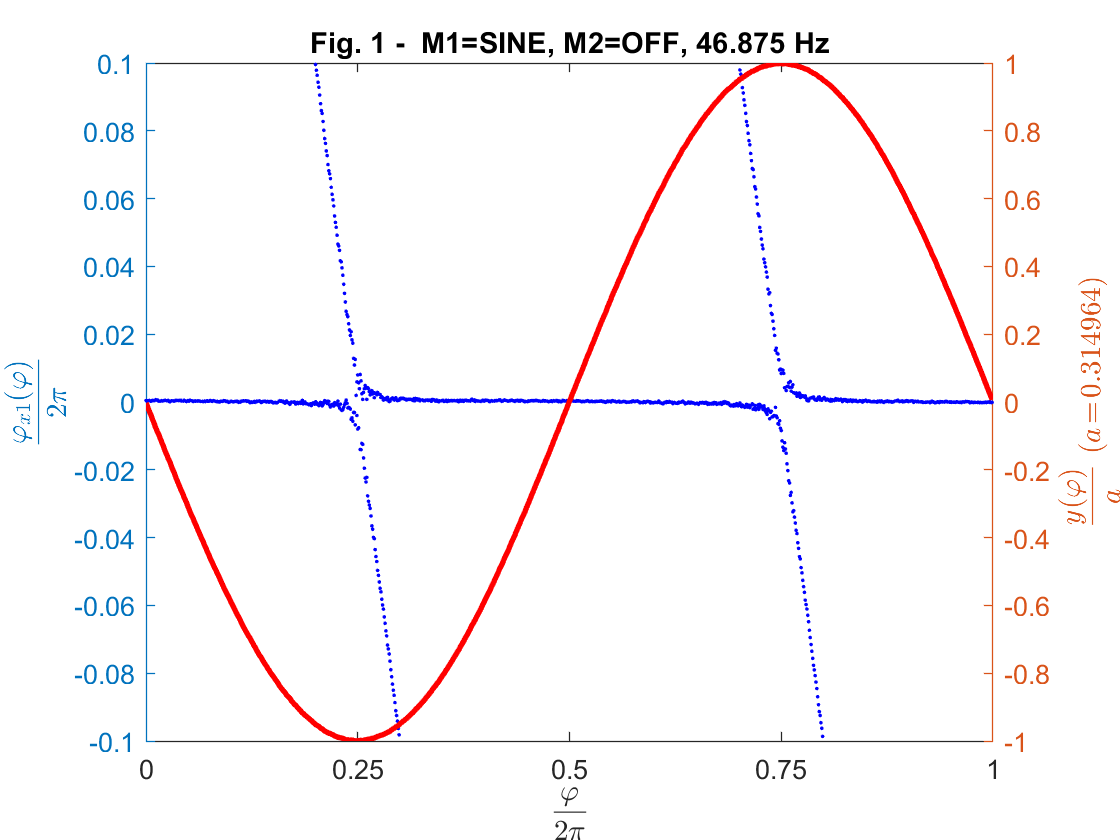

k     = 0:rec.K-1;
y     = rec.wave/rec.a;
x2    = sin(2*pi.*k/rec.K-pi); % The carrier signal to be modulated
phix1 = vVZtools.pmInvert(y,x2);
ft    = sprintf('Fig. 1 -  %s',rec.name);
plotPmInvert(y,phix1,[],ft,[-0.1 0.1],rec.a);

We see that, as expected, $\varphi_{x1}(t)\approx 0$ (Fig. 1). Now we analyze modulated signals (recordings #2...#12).

M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=00
vVZtools.loadRecording(rid="recordings/phaseModulationAnalysis/M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=00")
- Read wave file "../waves/recordings/phaseModulationAnalysis/M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=00.wav"
  - OK, 131760 samples
- Read annotation file "../labels/recordings/phaseModulationAnalysis/M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=00.par"
  - Read properties
    - OK, 14 properties
  - Read pitch marks
    - OK, 71 pitch marks
- Cycle data
    name: 'M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=00'
    wave: [1024×1 double]
      k0: 24249
       K: 1024
       a: 0.2180
       h: 0



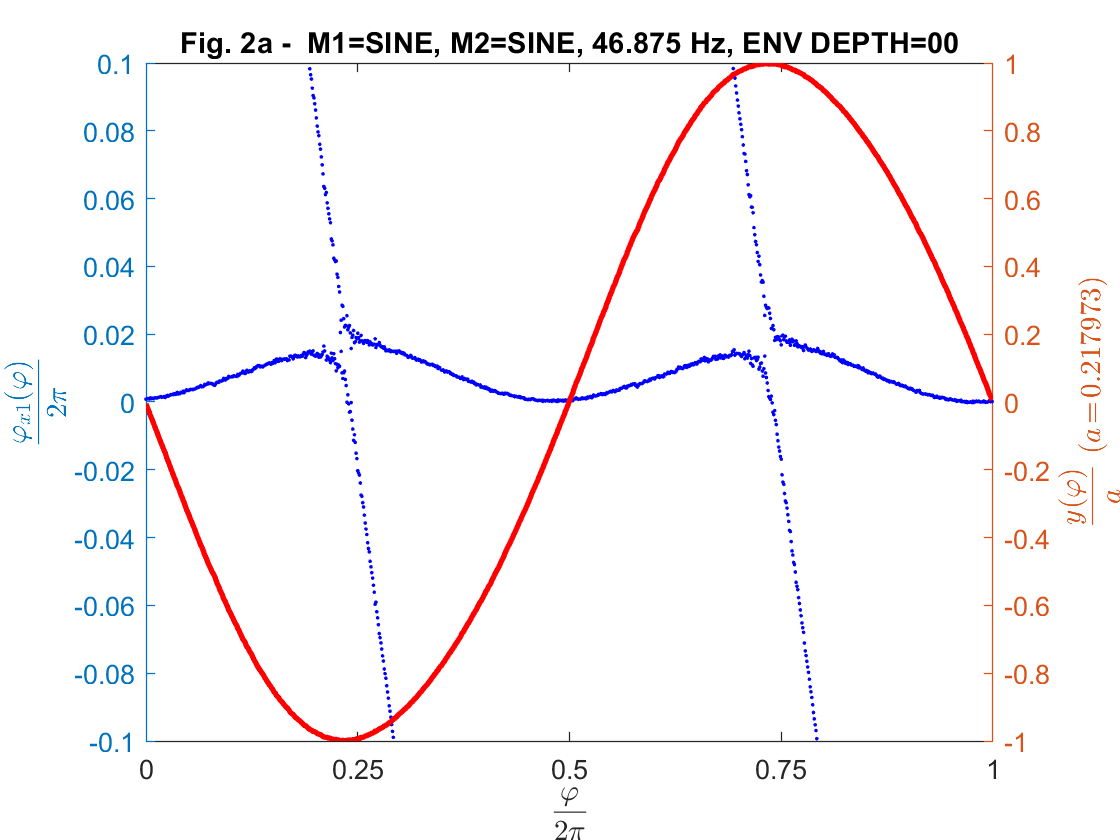

M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=09
vVZtools.loadRecording(rid="recordings/phaseModulationAnalysis/M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=09")
- Read wave file "../waves/recordings/phaseModulationAnalysis/M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=09.wav"
  - OK, 73260 samples
- Read annotation file "../labels/recordings/phaseModulationAnalysis/M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=09.par"
  - Read properties
    - OK, 14 properties
  - Read pitch marks
    - OK, 41 pitch marks
- Cycle data
    name: 'M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=09'
    wave: [1024×1 double]
      k0: 25473
       K: 1024
       a: 0.3290
       h: 0.0900



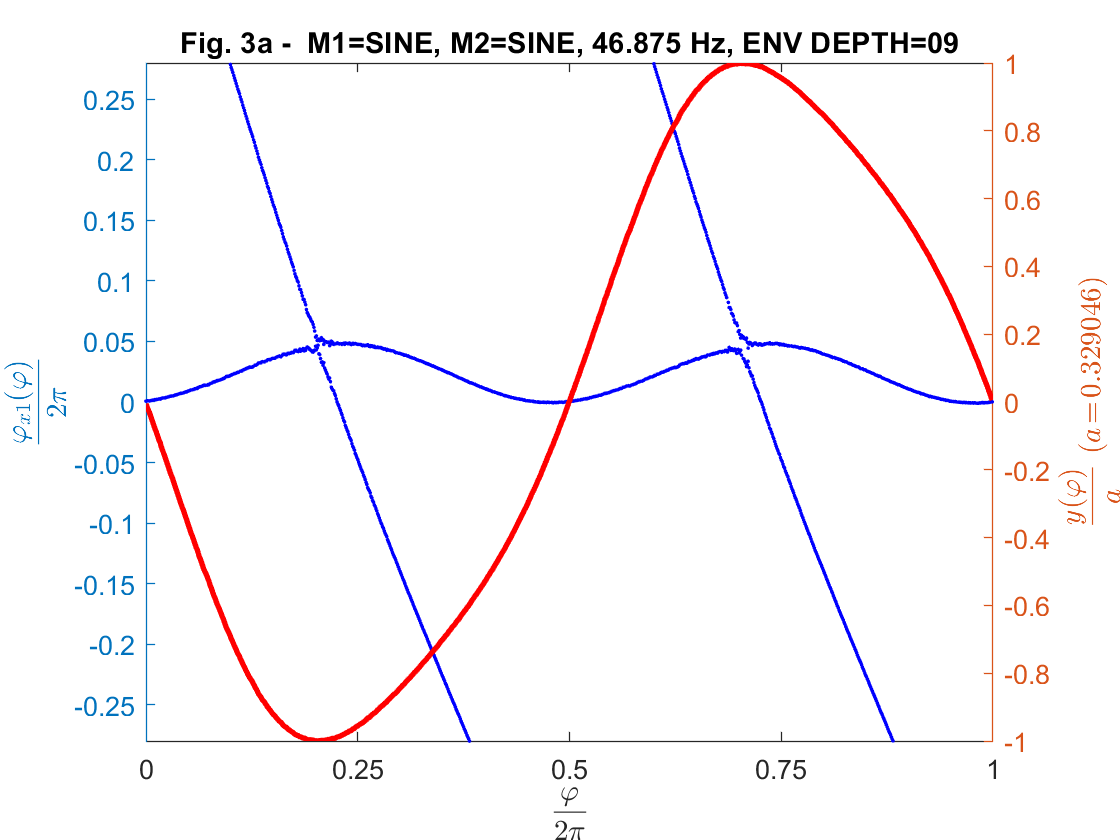

M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=19
vVZtools.loadRecording(rid="recordings/phaseModulationAnalysis/M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=19")
- Read wave file "../waves/recordings/phaseModulationAnalysis/M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=19.wav"
  - OK, 62760 samples
- Read annotation file "../labels/recordings/phaseModulationAnalysis/M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=19.par"
  - Read properties
    - OK, 14 properties
  - Read pitch marks
    - OK, 37 pitch marks
- Cycle data
    name: 'M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=19'
    wave: [1024×1 double]
      k0: 15971
       K: 1024
       a: 0.3890
       h: 0.1900



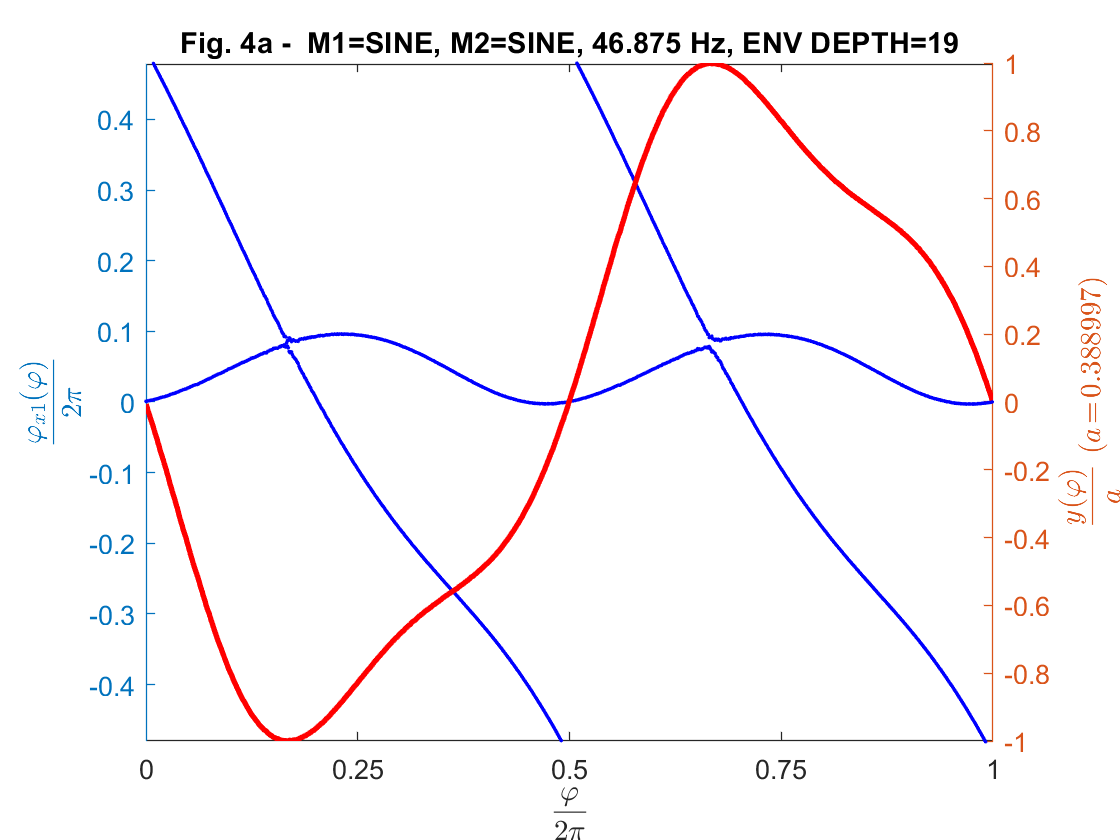

M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=29
vVZtools.loadRecording(rid="recordings/phaseModulationAnalysis/M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=29")
- Read wave file "../waves/recordings/phaseModulationAnalysis/M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=29.wav"
  - OK, 52260 samples
- Read annotation file "../labels/recordings/phaseModulationAnalysis/M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=29.par"
  - Read properties
    - OK, 14 properties
  - Read pitch marks
    - OK, 41 pitch marks
- Cycle data
    name: 'M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=29'
    wave: [1024×1 double]
      k0: 12621
       K: 1024
       a: 0.4156
       h: 0.2900



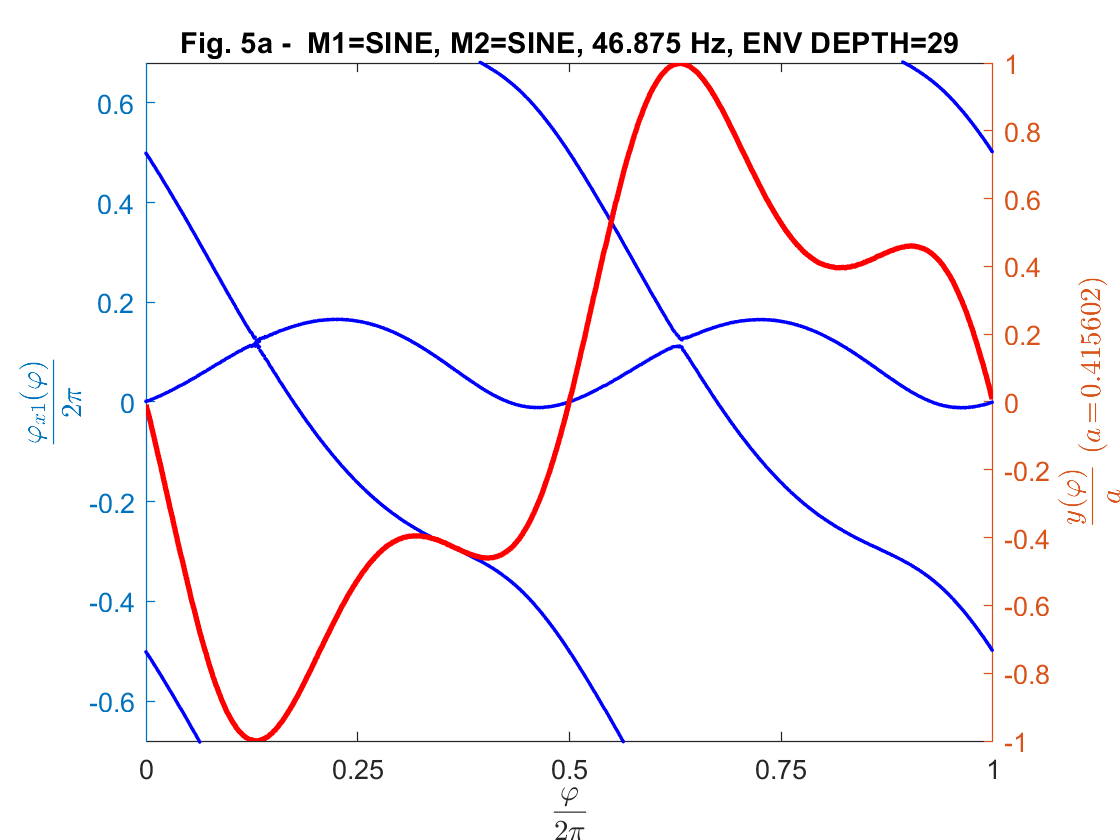

M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=39
vVZtools.loadRecording(rid="recordings/phaseModulationAnalysis/M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=39")
- Read wave file "../waves/recordings/phaseModulationAnalysis/M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=39.wav"
  - OK, 55260 samples
- Read annotation file "../labels/recordings/phaseModulationAnalysis/M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=39.par"
  - Read properties
    - OK, 14 properties
  - Read pitch marks
    - OK, 38 pitch marks
- Cycle data
    name: 'M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=39'
    wave: [1024×1 double]
      k0: 17834
       K: 1024
       a: 0.3924
       h: 0.3900



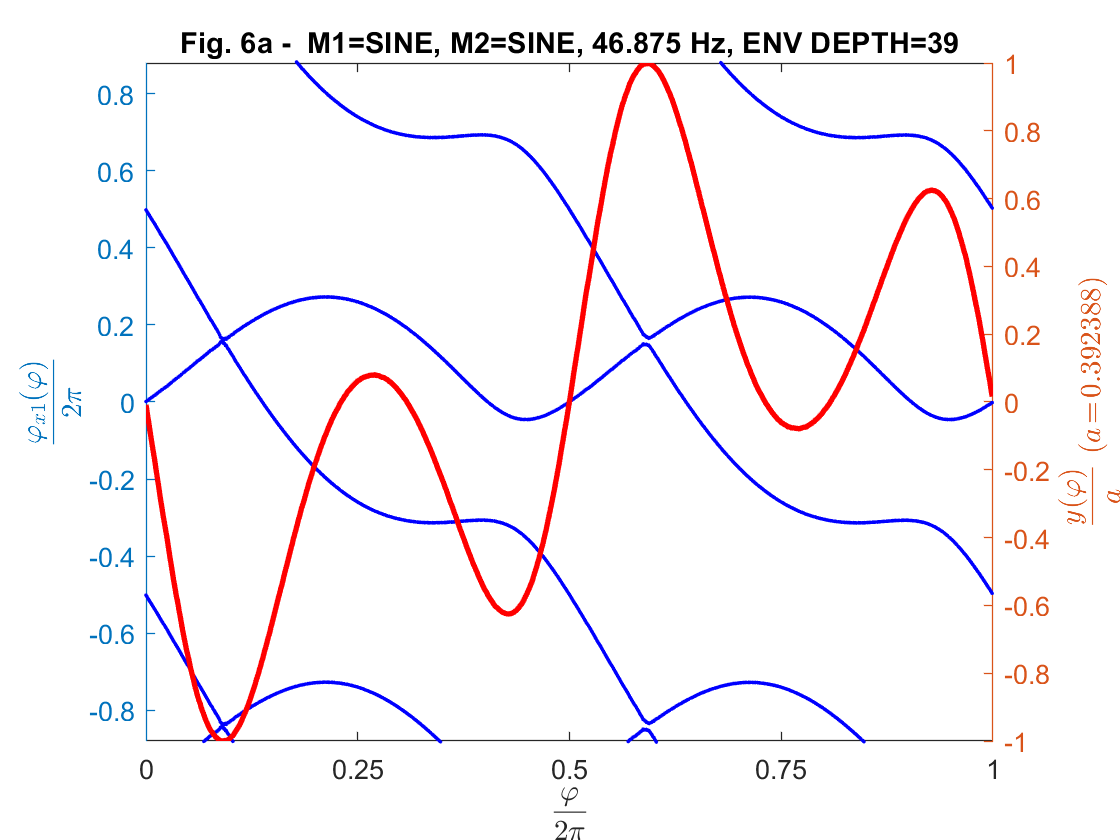

M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=49
vVZtools.loadRecording(rid="recordings/phaseModulationAnalysis/M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=49")
- Read wave file "../waves/recordings/phaseModulationAnalysis/M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=49.wav"
  - OK, 53760 samples
- Read annotation file "../labels/recordings/phaseModulationAnalysis/M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=49.par"
  - Read properties
    - OK, 14 properties
  - Read pitch marks
    - OK, 38 pitch marks
- Cycle data
    name: 'M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=49'
    wave: [1024×1 double]
      k0: 11511
       K: 1024
       a: 0.3589
       h: 0.4900



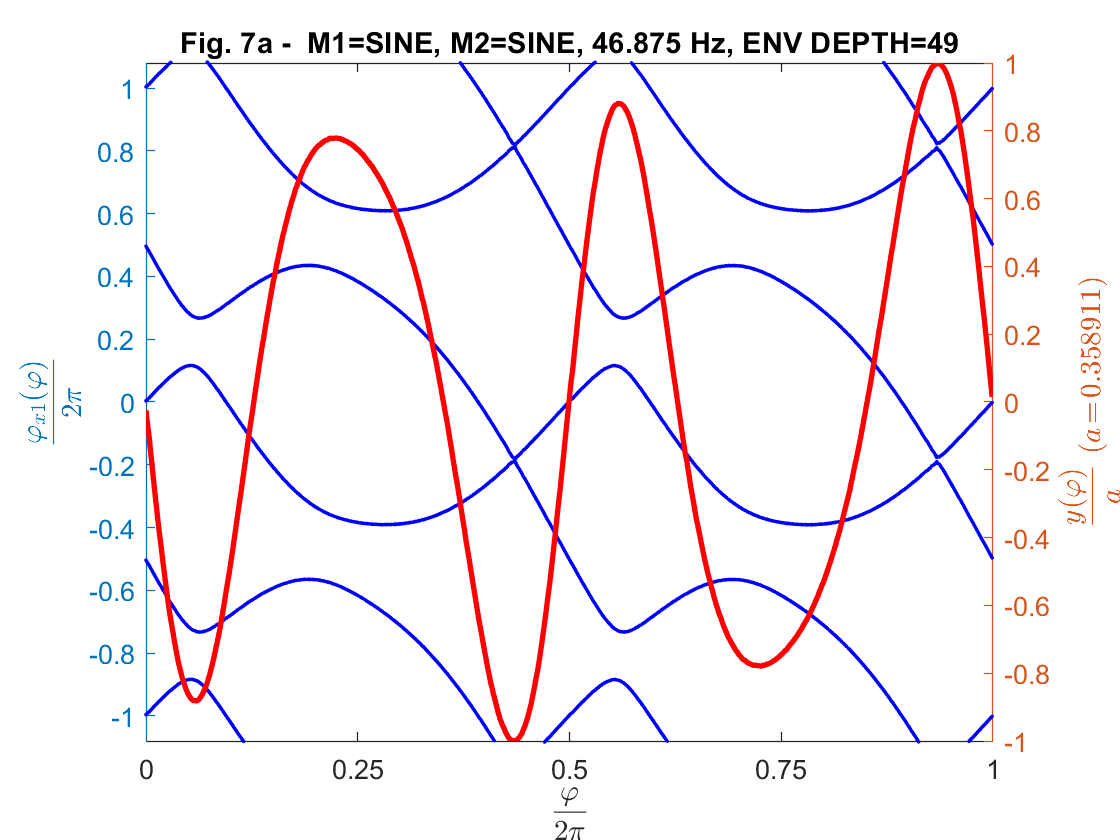

M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=59
vVZtools.loadRecording(rid="recordings/phaseModulationAnalysis/M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=59")
- Read wave file "../waves/recordings/phaseModulationAnalysis/M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=59.wav"
  - OK, 49260 samples
- Read annotation file "../labels/recordings/phaseModulationAnalysis/M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=59.par"
  - Read properties
    - OK, 14 properties
  - Read pitch marks
    - OK, 37 pitch marks
- Cycle data
    name: 'M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=59'
    wave: [1024×1 double]
      k0: 11262
       K: 1024
       a: 0.4256
       h: 0.5900



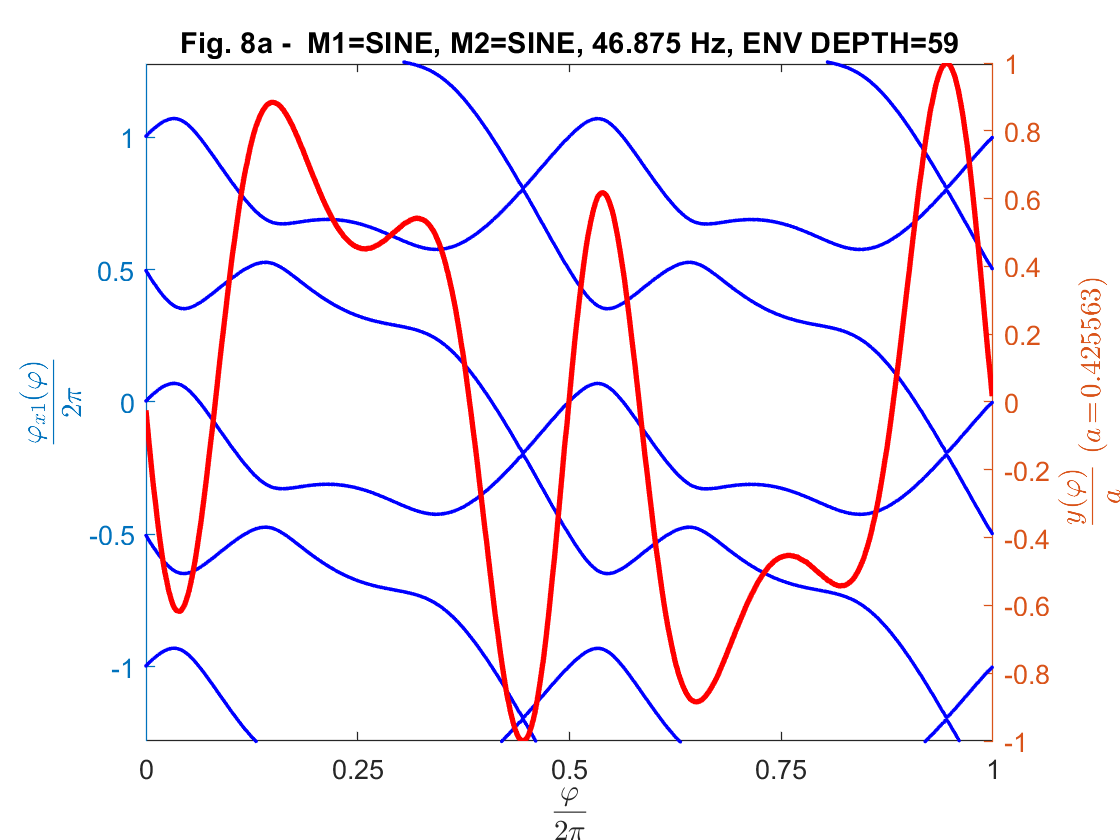

M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=69
vVZtools.loadRecording(rid="recordings/phaseModulationAnalysis/M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=69")
- Read wave file "../waves/recordings/phaseModulationAnalysis/M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=69.wav"
  - OK, 61260 samples
- Read annotation file "../labels/recordings/phaseModulationAnalysis/M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=69.par"
  - Read properties
    - OK, 14 properties
  - Read pitch marks
    - OK, 38 pitch marks
- Cycle data
    name: 'M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=69'
    wave: [1024×1 double]
      k0: 13297
       K: 1024
       a: 0.3413
       h: 0.6900



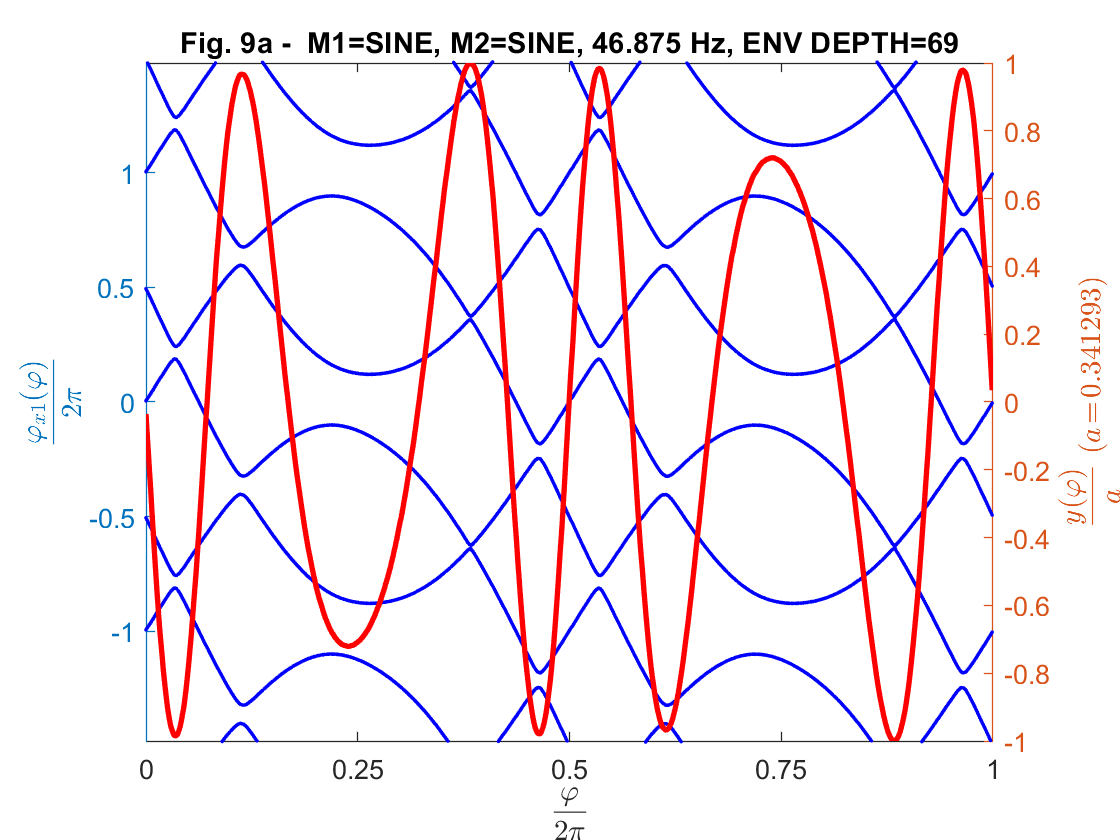

M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=79
vVZtools.loadRecording(rid="recordings/phaseModulationAnalysis/M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=79")
- Read wave file "../waves/recordings/phaseModulationAnalysis/M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=79.wav"
  - OK, 68760 samples
- Read annotation file "../labels/recordings/phaseModulationAnalysis/M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=79.par"
  - Read properties
    - OK, 14 properties
  - Read pitch marks
    - OK, 36 pitch marks
- Cycle data
    name: 'M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=79'
    wave: [1024×1 double]
      k0: 21870
       K: 1024
       a: 0.4130
       h: 0.7900



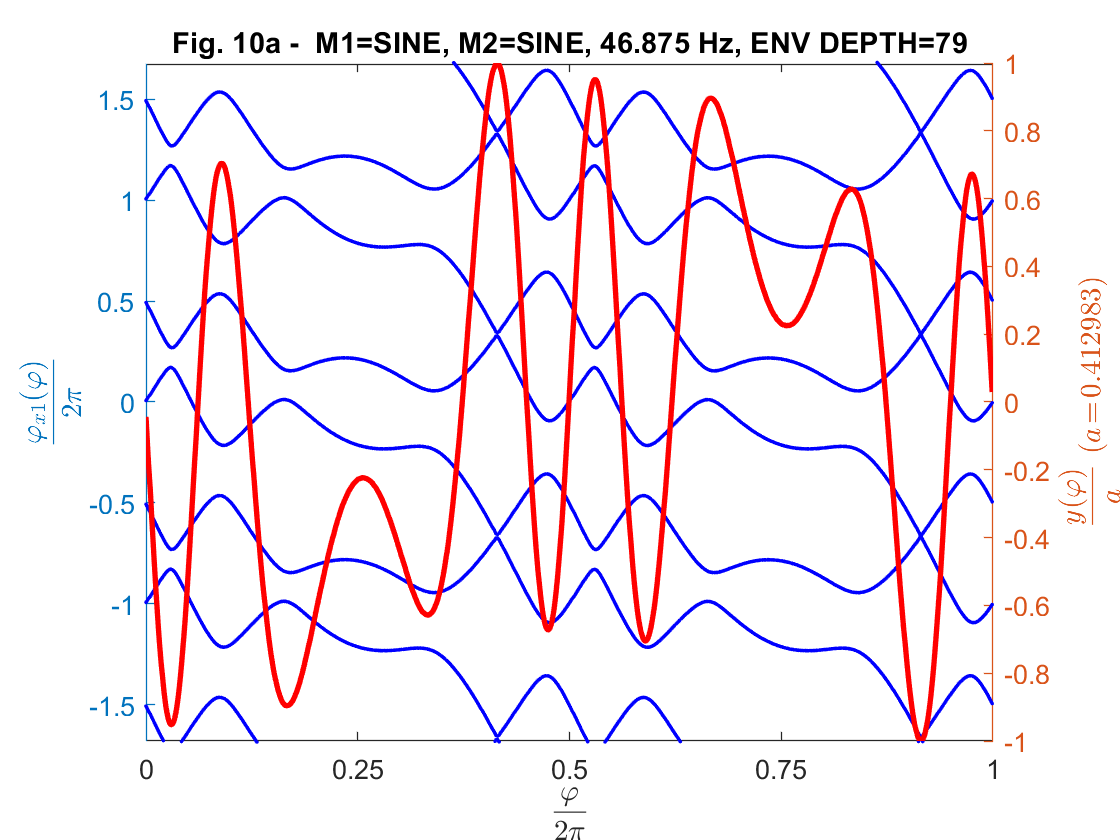

M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=89
vVZtools.loadRecording(rid="recordings/phaseModulationAnalysis/M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=89")
- Read wave file "../waves/recordings/phaseModulationAnalysis/M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=89.wav"
  - OK, 61260 samples
- Read annotation file "../labels/recordings/phaseModulationAnalysis/M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=89.par"
  - Read properties
    - OK, 14 properties
  - Read pitch marks
    - OK, 39 pitch marks
- Cycle data
    name: 'M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=89'
    wave: [1024×1 double]
      k0: 13132
       K: 1024
       a: 0.3934
       h: 0.8900



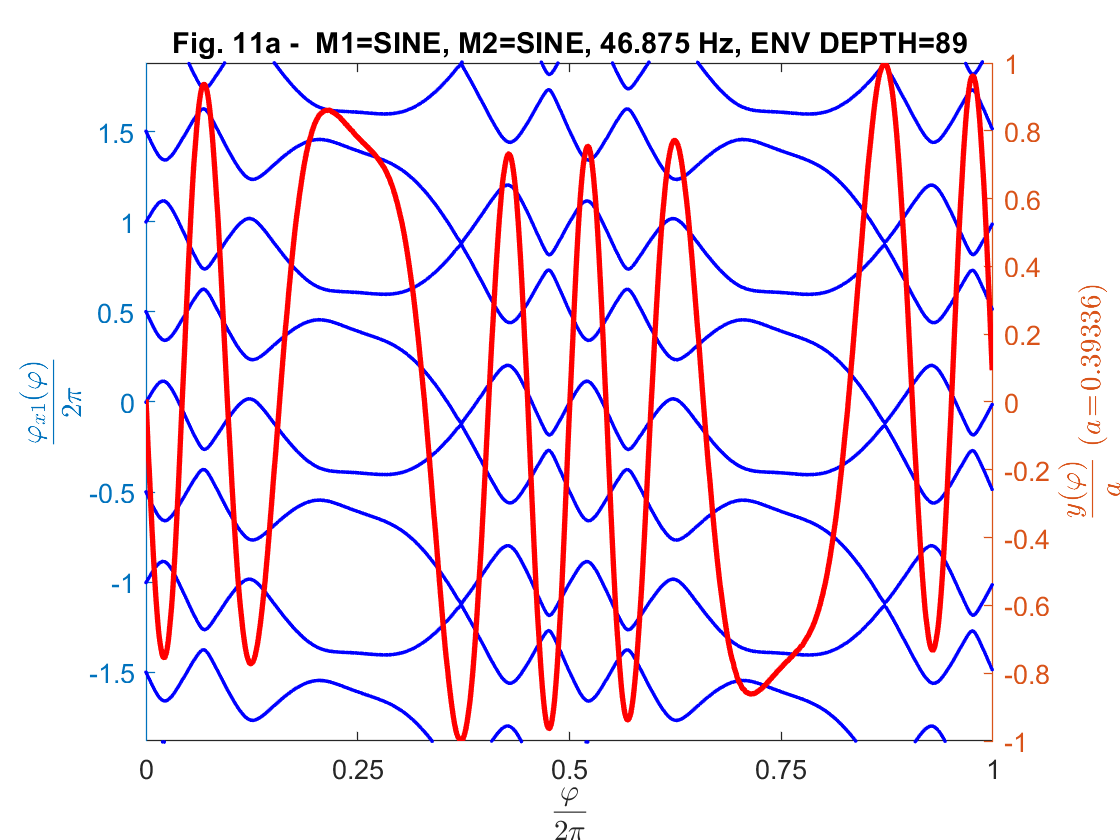

M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=99
vVZtools.loadRecording(rid="recordings/phaseModulationAnalysis/M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=99")
- Read wave file "../waves/recordings/phaseModulationAnalysis/M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=99.wav"
  - OK, 58260 samples
- Read annotation file "../labels/recordings/phaseModulationAnalysis/M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=99.par"
  - Read properties
    - OK, 14 properties
  - Read pitch marks
    - OK, 39 pitch marks
- Cycle data
    name: 'M1=SINE, M2=SINE, 46.875 Hz, ENV DEPTH=99'
    wave: [1024×1 double]
      k0: 12452
       K: 1024
       a: 0.3918
       h: 0.9900



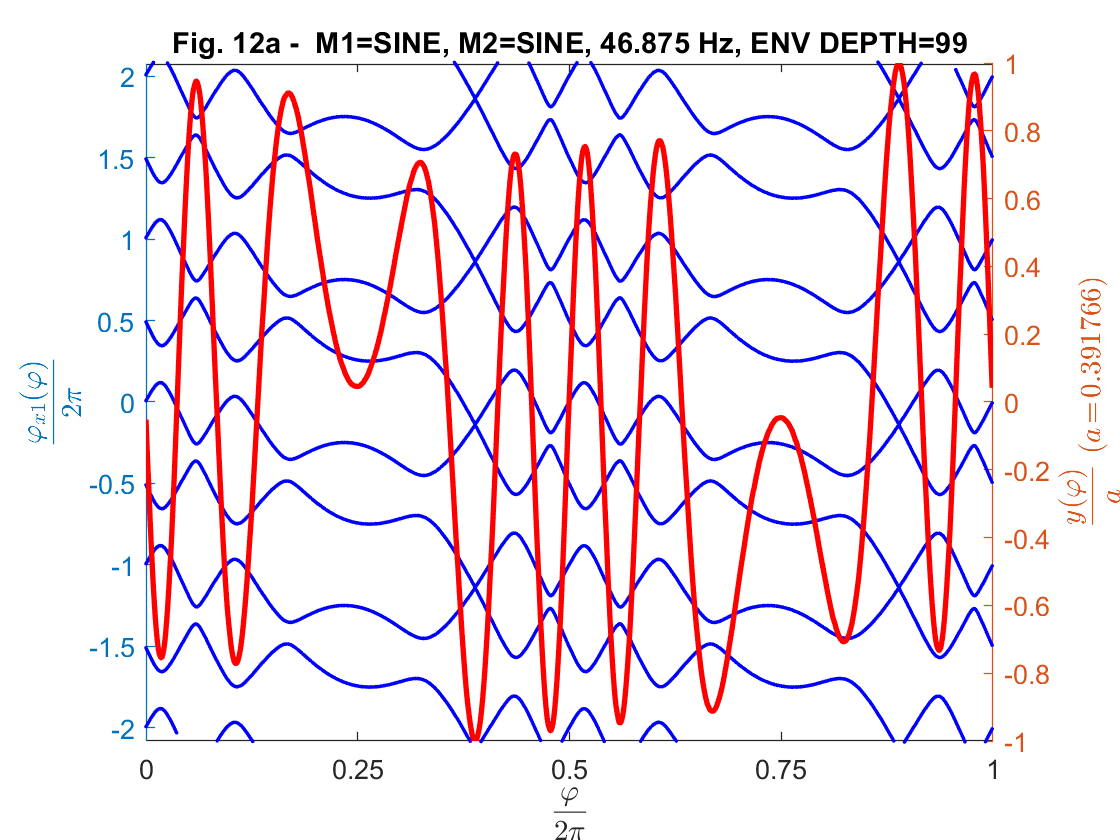

rlst = vVZtools.listRecordings([pfx '.*M1=SINE, M2=SINE*']);
rec1 = cell(0);
FF   = 2; % First figure index
for i=1:length(rlst)
  rec   = loadRecordings(rlst(i),1024); fprintf('- Cycle data\n'); disp(rec);
  k     = 0:rec.K-1;
  y     = rec.wave/rec.a;
  x2    = sin(2*pi.*k/rec.K-pi); % The carrier signal to be modulated
  phix1 = vVZtools.pmInvert(y,x2);
  ft    = sprintf('Fig. %da -  %s',FF+i-1,rec.name);
  yl    = [-2*rec.h-0.1 2*rec.h+0.1];
  plotPmInvert(y,phix1,[],ft,yl,rec.a);
  rec.phix1 = phix1;
  rec1{i} = rec;
end

Figs. 2 through 6 (`ENV DEPTH` $\in$ [ `00`, `09`, `19`, `29`, `39` ]) indicate, that $x_2$ might be phase-modulated with the *square* of $x_1$:

    $\varphi_{x1}(\varphi) = 2\pi\,h\,x_1^2(\varphi)$   or, as $x_1$ is itself a VZ-style sine,   $\varphi_{x1}(\varphi)=2\pi\,h\,\sin^2(\varphi-\pi)$.

I assume that $x_1$ takes values in $[-1,1]$, hence the gain of $2\pi$ to make it a phase signal. Further I introduced a modulation index (or modulation depth) $h$. The modulated signal would then be

    $y(\varphi) = a\,\sin\big(\varphi-\pi + 2\pi\,h\,\sin^2(\varphi-\pi)\big)$.

In the Figures I observe that 

- already at `ENV DEPTH=00` there seems to be some modulation,

- the squared sine---if it is a squared sine---exposes little phase and amplitude offsets.

The remaining plots are just a big mess; probably due to phase wrapping... :(

Let's test the square hypothesis. I first read the positions $k_{2\max}$, $k_{2\min}$ and values $\varphi_{2\max}$, $\varphi_{2\min}$ of first maximum and the last minimum the (blue) "squared sines". Then I model the phase function $\varphi_{x1}(\varphi)$ by

    
$$\varphi_{x1,\text{ MODEL}}(\varphi)=2\pi\,\varphi_{2\max}\,\sin^2\left(\varphi-\pi\right)$$


and plot the locations of the maxima, the model phase function and the original phase function.

fprintf(['_____________________________________________________________________\n' ...
 'Test Model']);

_____________________________________________________________________
Test Model

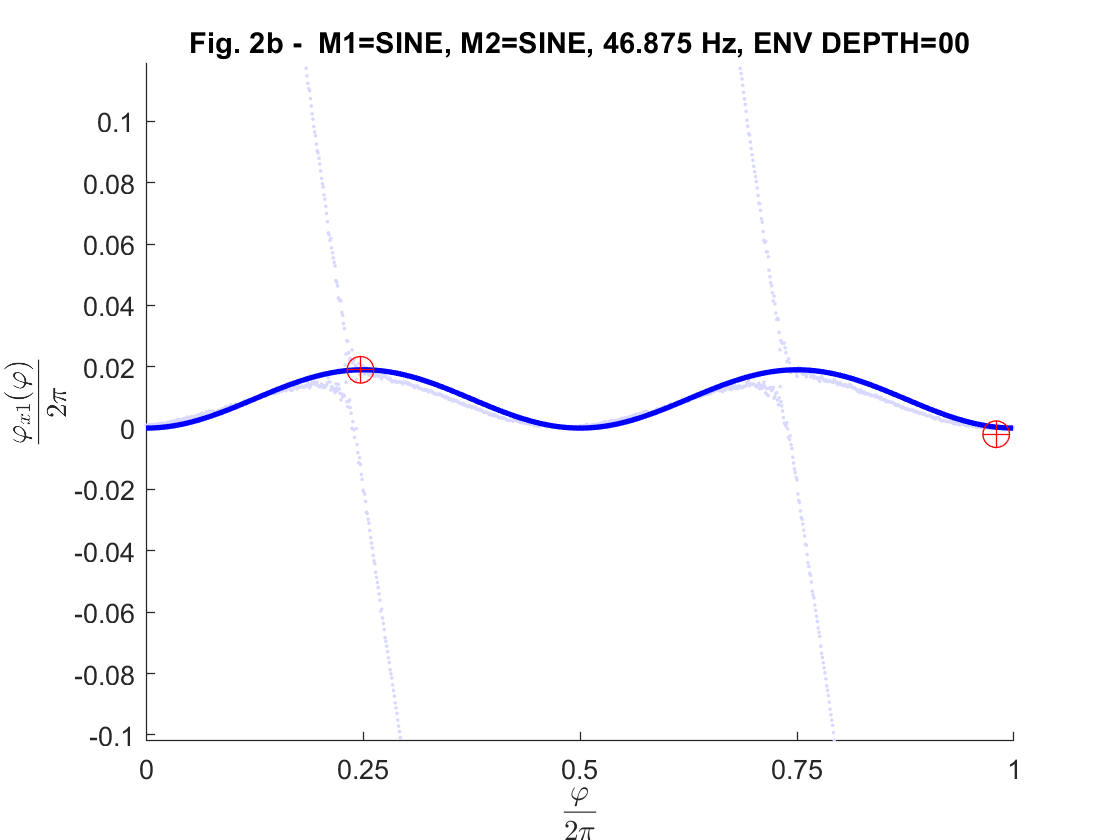

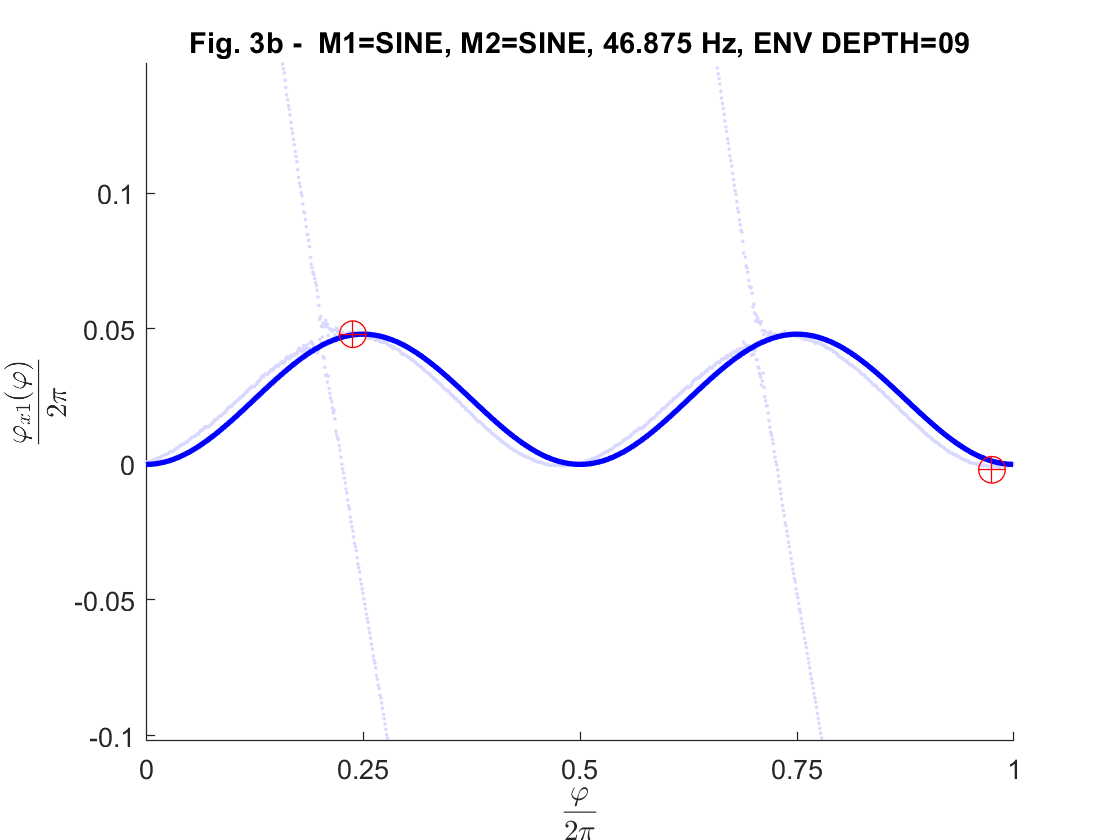

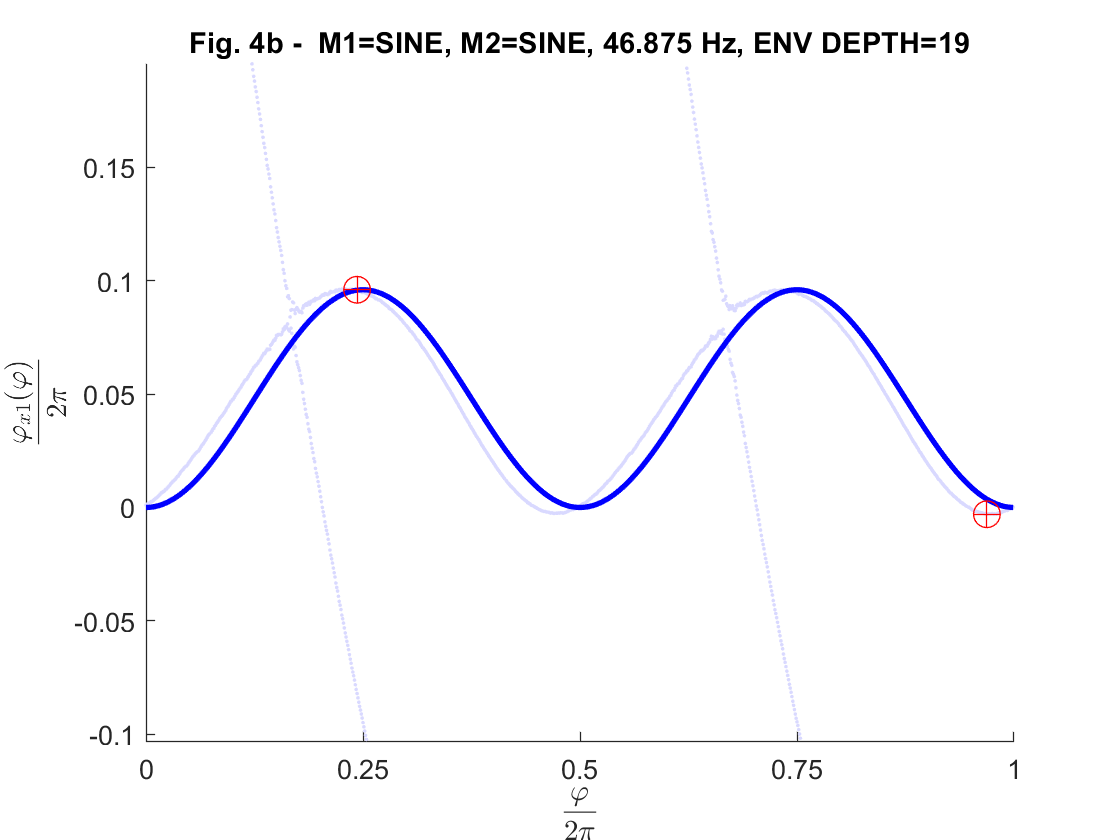

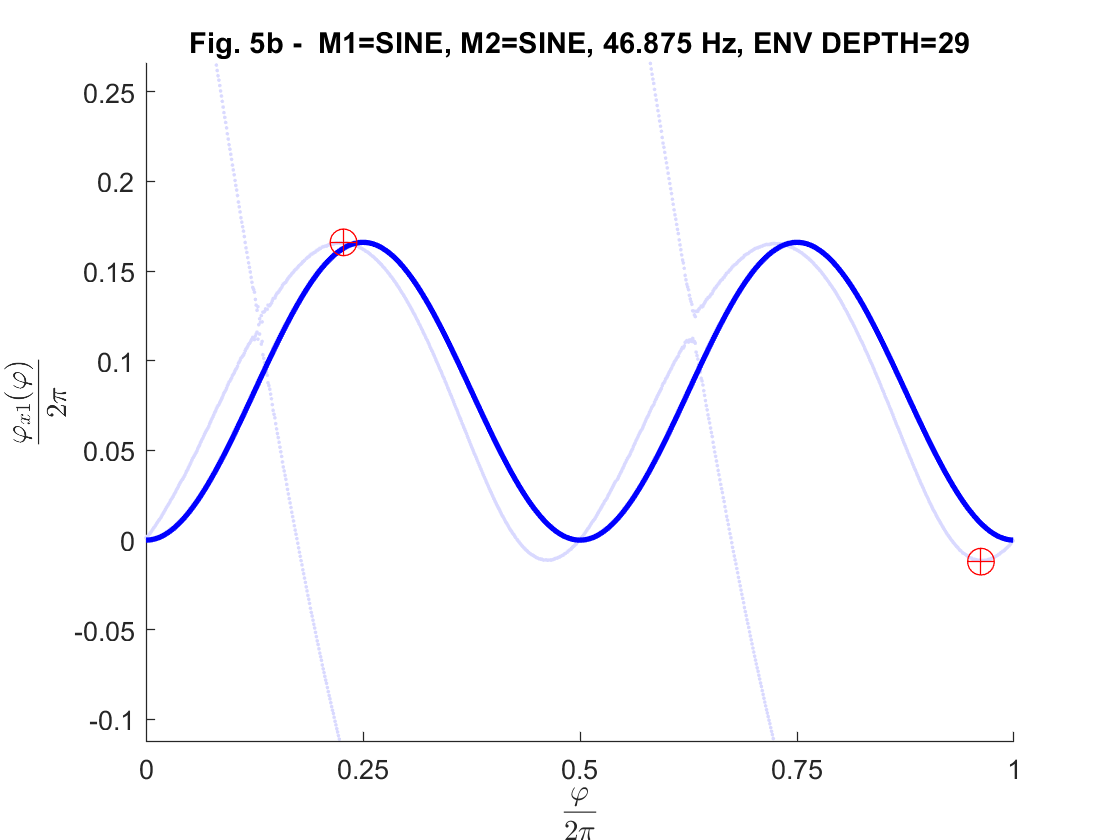

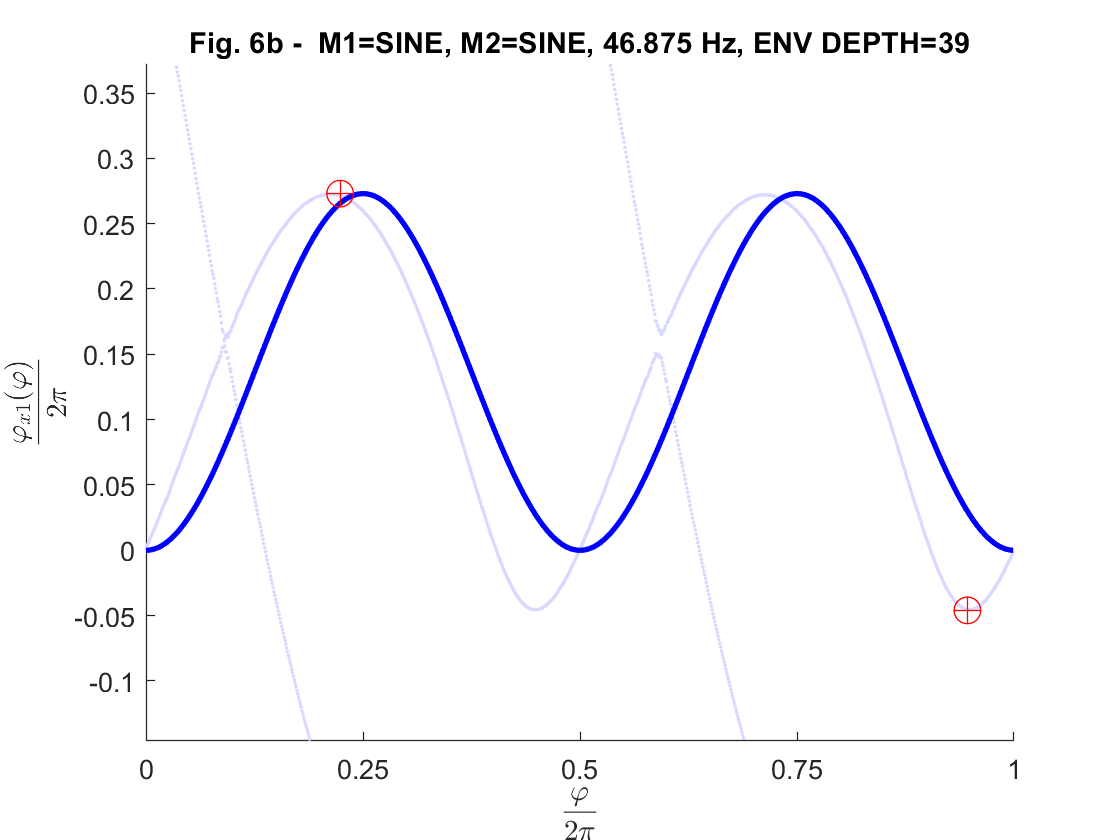

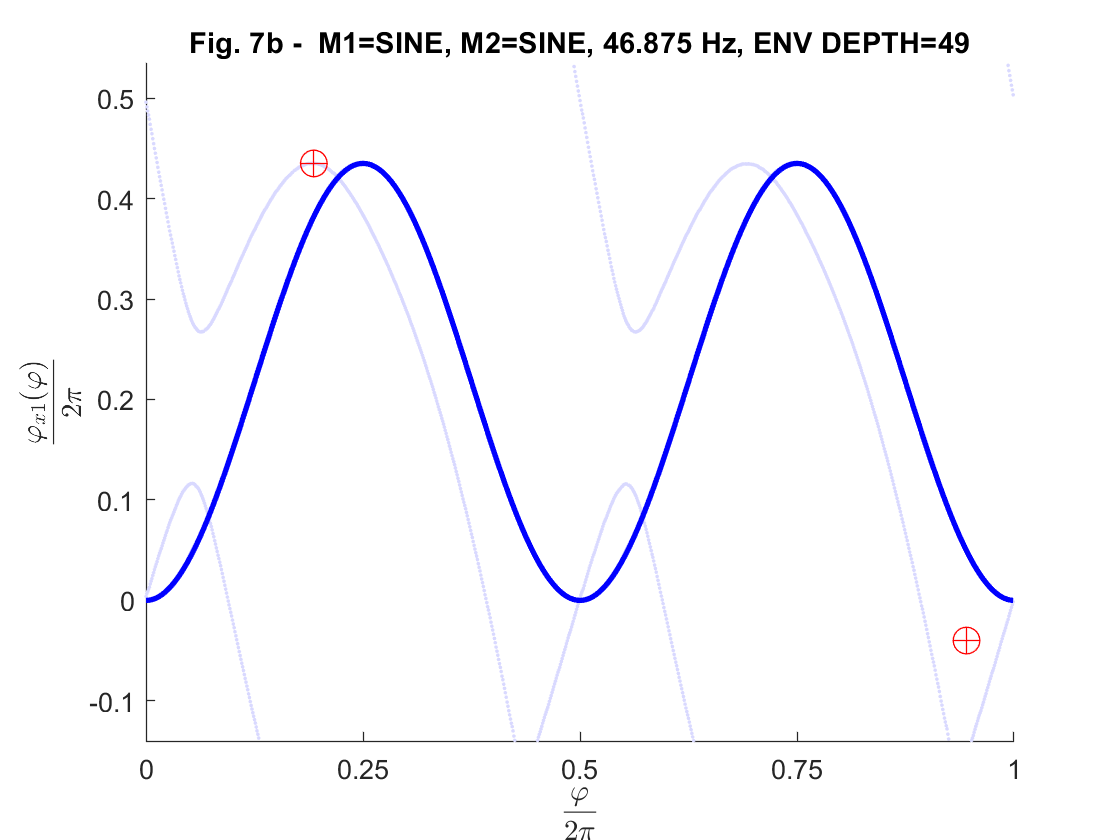

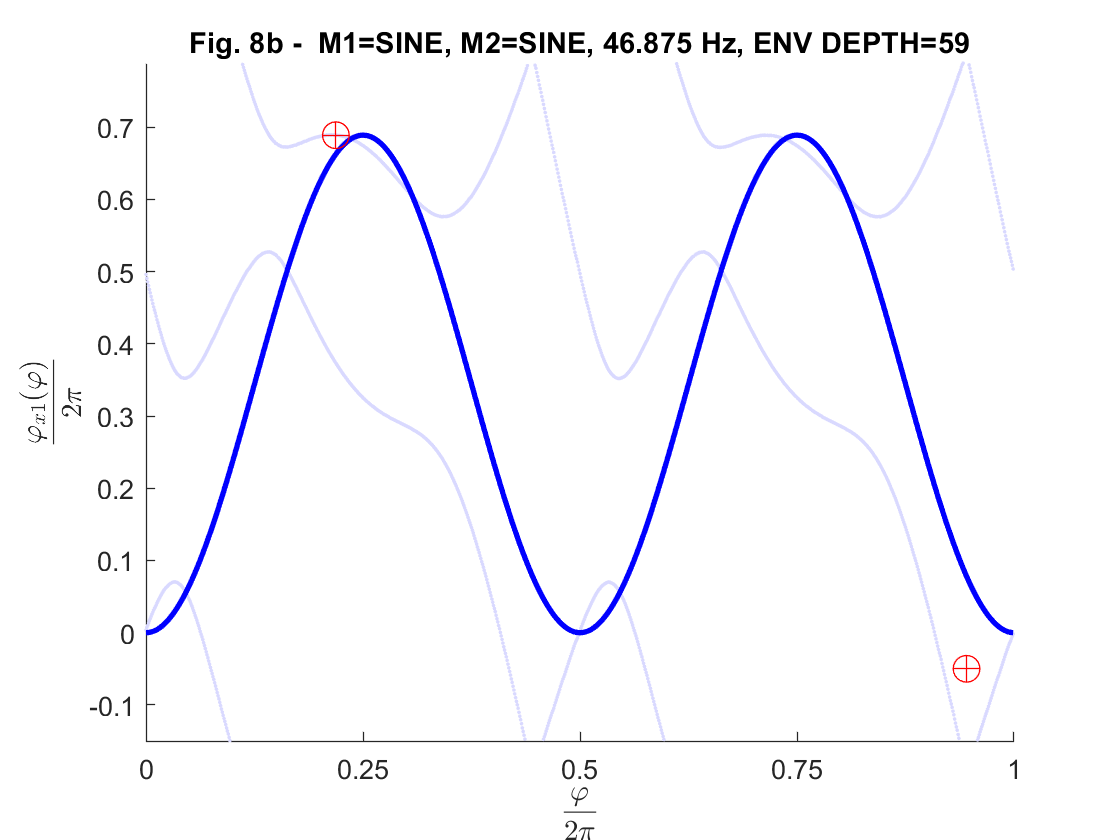

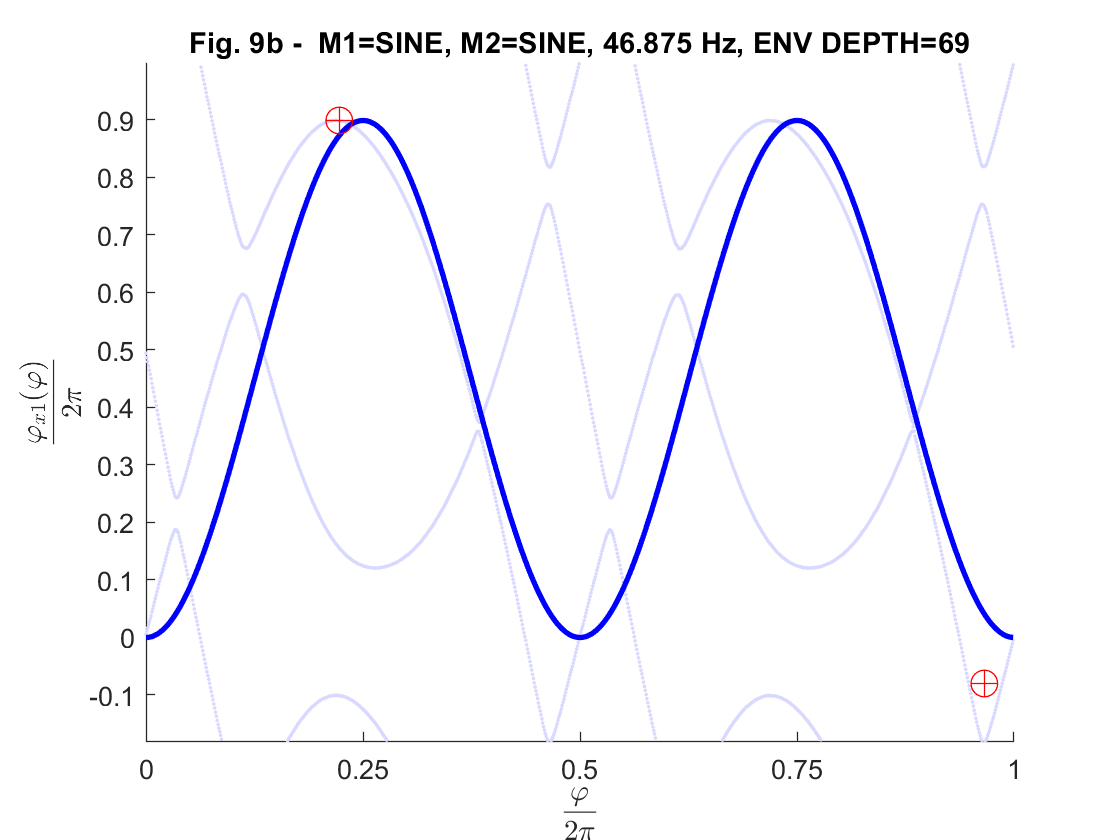


% ENV DEPTH:    00     09     19     29     39     49     59     69     79     89     99
phi2max =  [ 0.019; 0.048; 0.096; 0.166; 0.273; 0.435; 0.689; 0.899; 1.218; 1.5  ; 1.75 ];
k2max   =  [   253;   244;   249;   233;   229;   198;   224;   228;   243;   246;   245];
phi2min =  [-0.002;-0.002;-0.003;-0.012;-0.046;-0.04 ;-0.05 ;-0.08 ;-0.09 ;-0.10 ; -0.10];
k2min   =  [  1003;   998;   992;   985;   969;   968;   968;   989;  1001;   998;  1001];

for i=1:length(rec1)
  rec       = rec1{i};                                   % Current recording
  K         = rec.K;                                     % Cycle length
  k         = 0:K-1;                                     % Sample domain
  phix1_mea = rec.phix1;                                 % Measured modulating signal
  phix1_mod = phi2max(i)*(sin(2*pi.*k/K-pi)).^2;         % Modeled modulating signal
  ft        = sprintf('Fig. %db -  %s',FF+i-1,rec.name); % Figure title
  yl        = [phi2min(i)-0.1 phi2max(i)+0.1];           % Y axis limits
  mX        = [ k2max(i)   k2min(i)   ];                 % Markers, x-coordinates
  mY        = [ phi2max(i) phi2min(i) ];                 % Markers, y-coordinates
  plotPmModelPhase(phix1_mea,phix1_mod,ft,yl,mX,mY);     % Plot phase model 
end

Finally, I simulate the phase modulated signals

    
$$y_{\text{MODEL}}(\varphi) = \sin\big(\varphi-\pi+2\pi\,\varphi_{2\max}\,\sin^2(\varphi-\pi)\big)$$


and plot them together with the respective recorded waveforms $y_{\text{REC}}(\varphi)$:

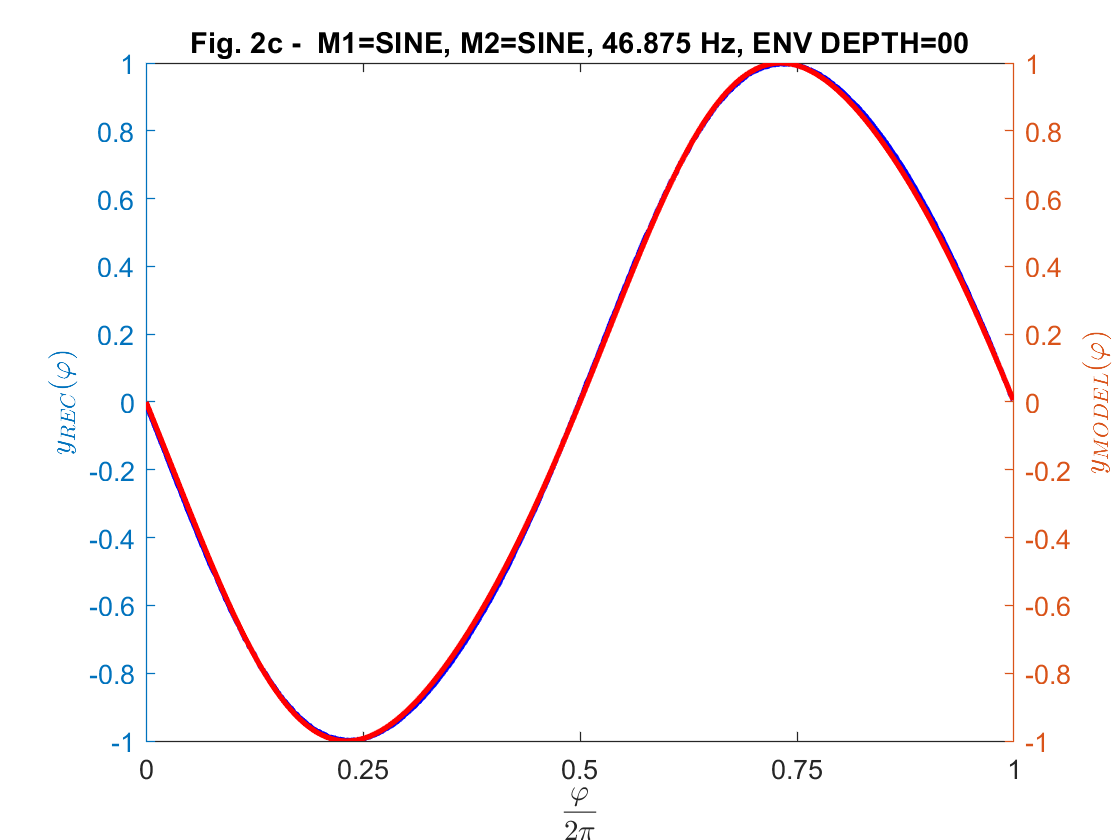

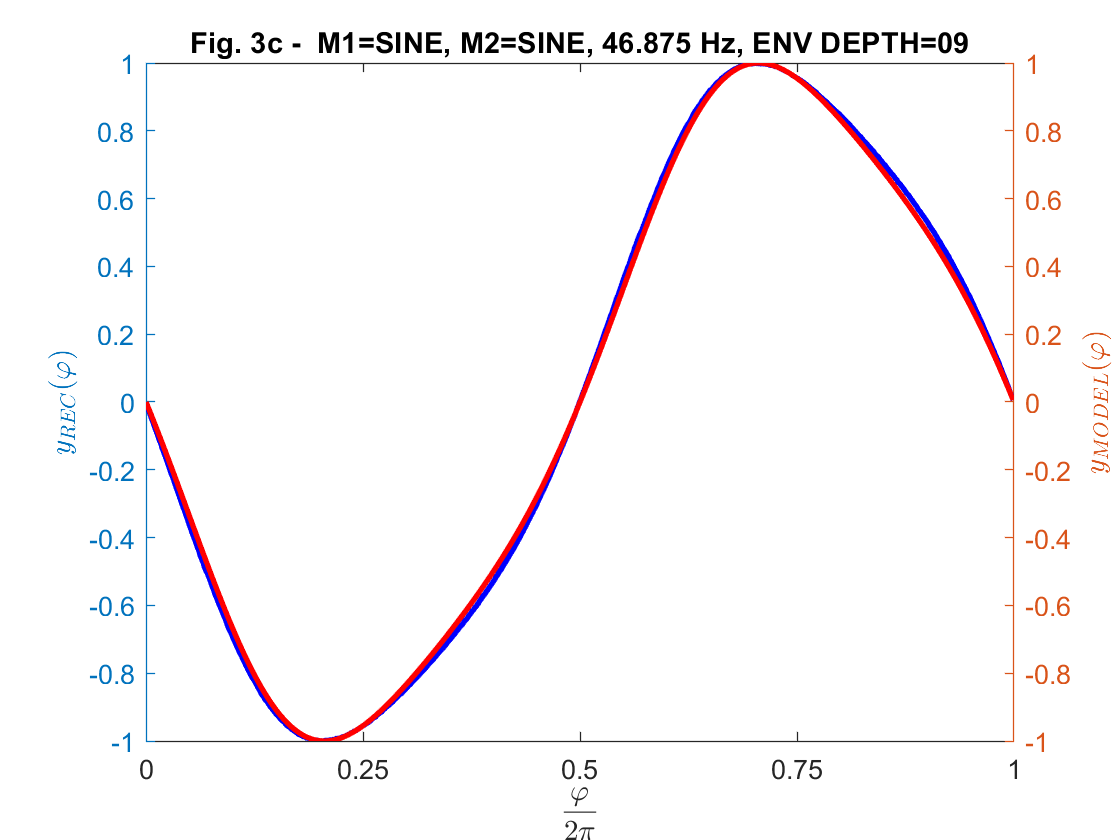

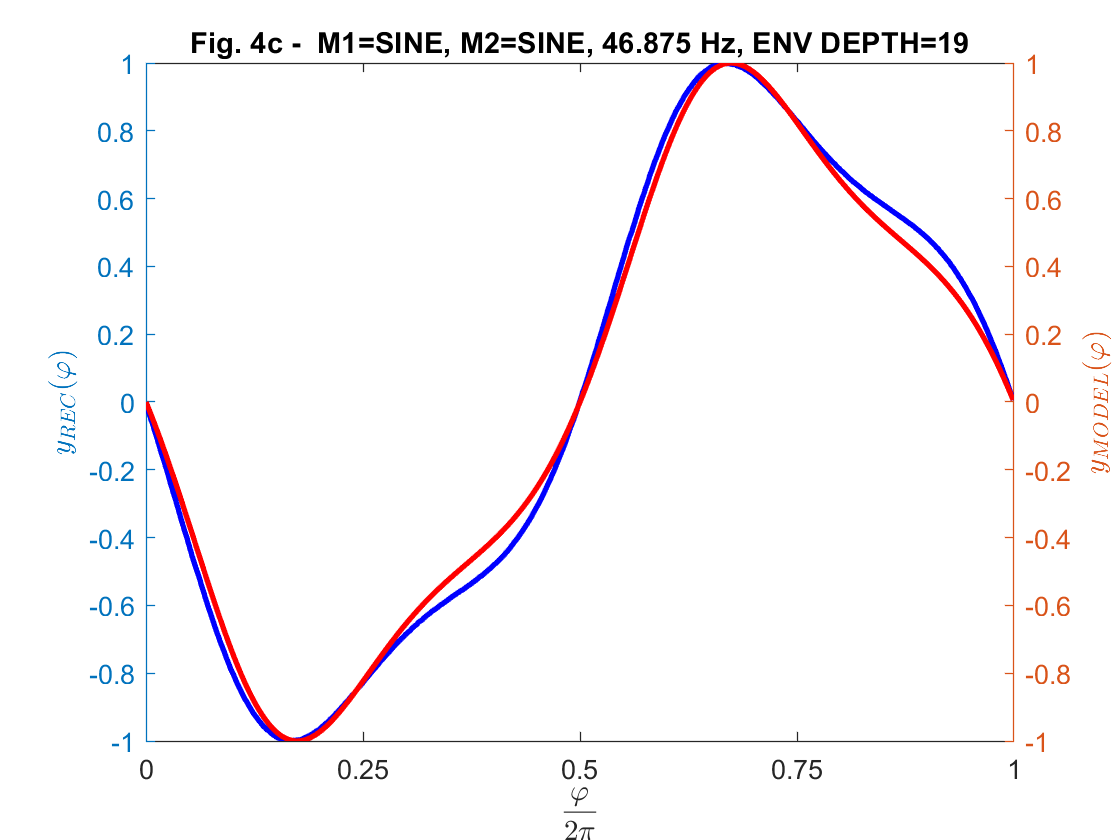

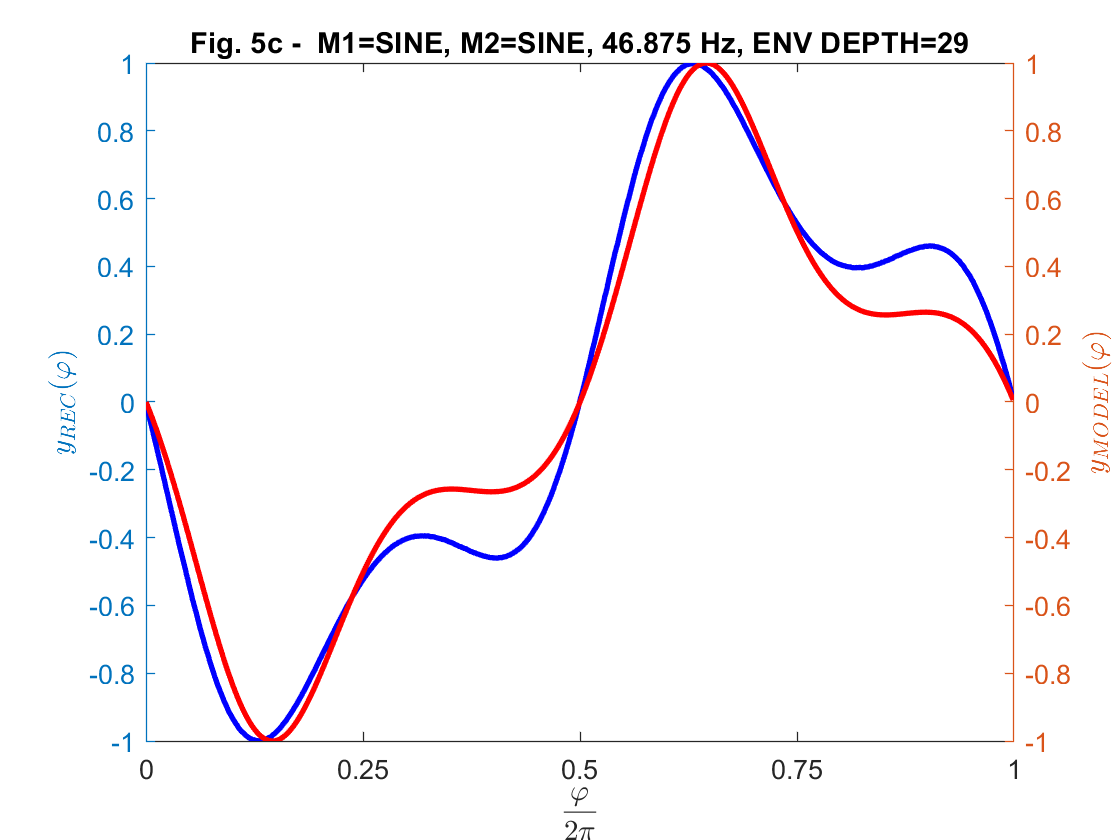

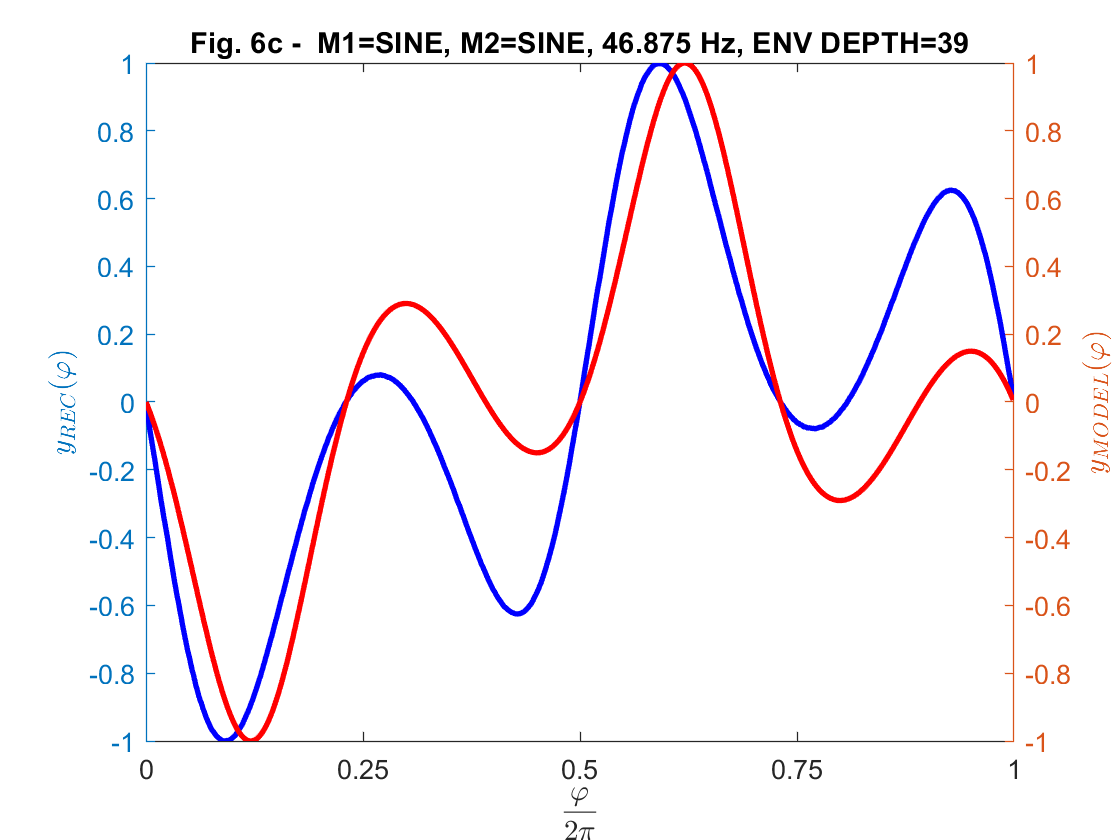

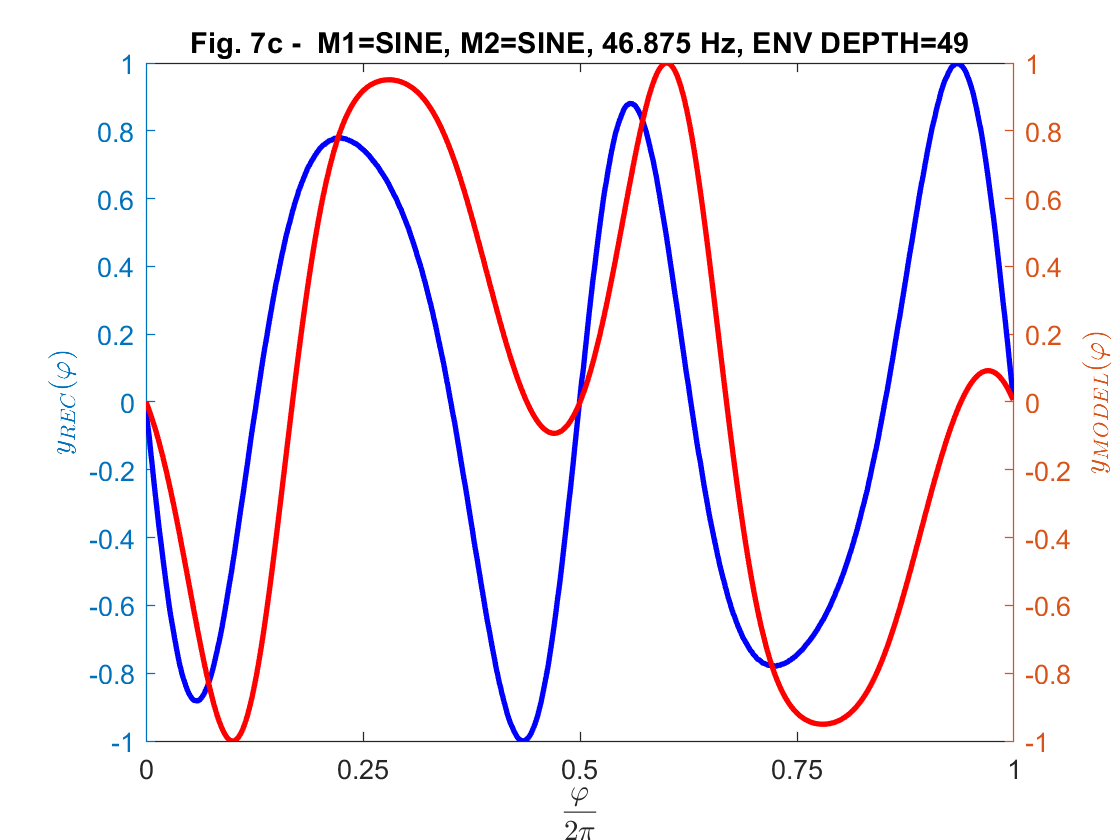

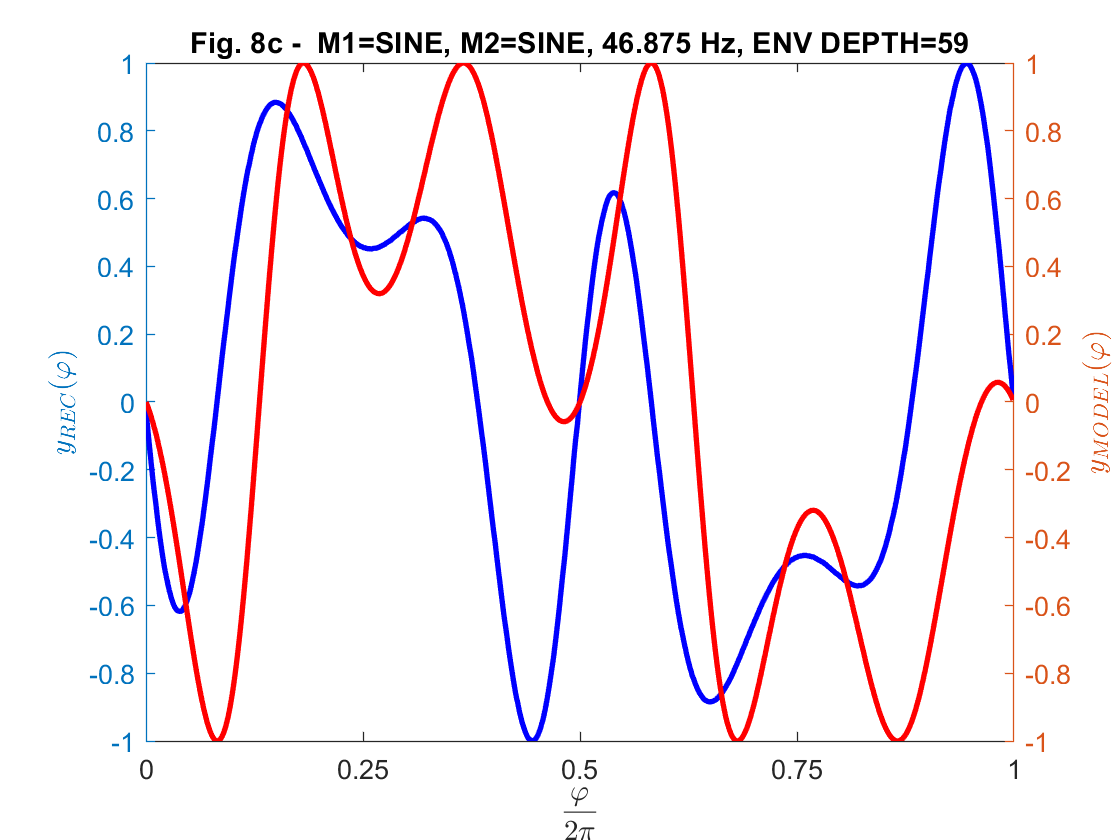

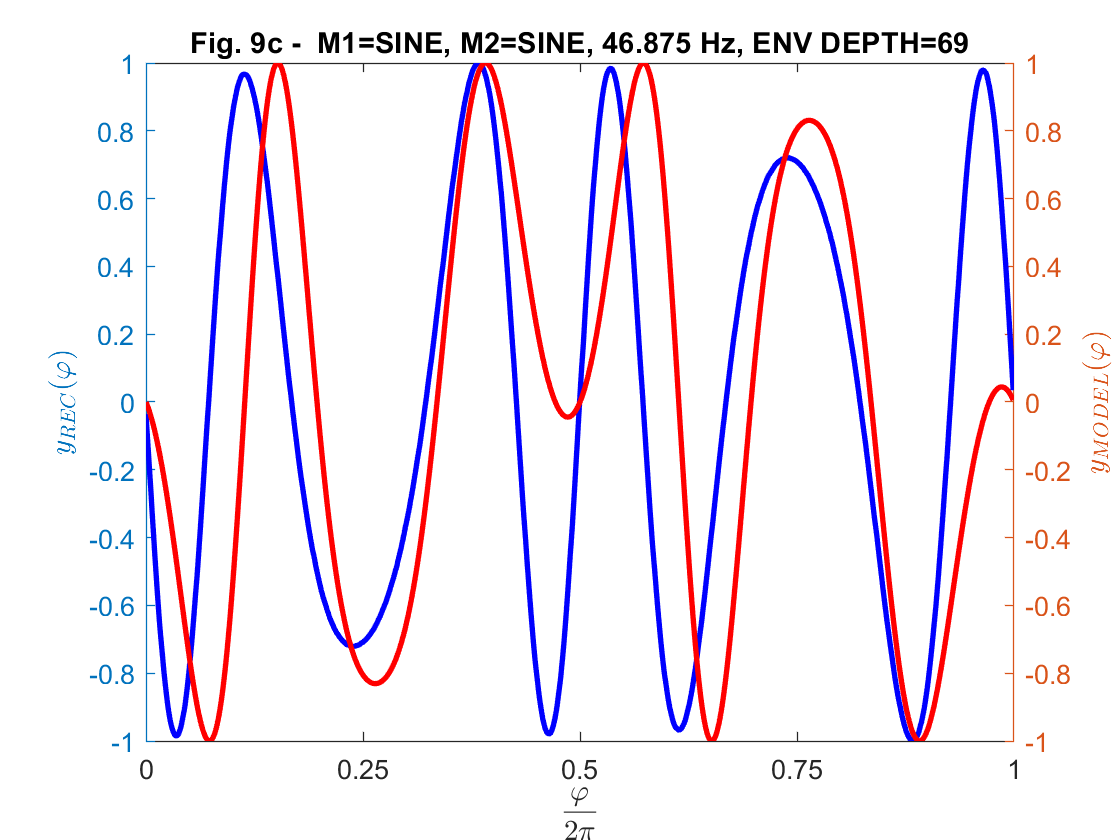

for i=1:length(rec1)
  rec = rec1{i};                                         % Current recording
  K     = rec.K;                                         % Cycle length
  k     = 0:K-1;                                         % Sample domain
  y_mea = rec.wave/rec.a;                                % Measured modulated signal
  y_mod = sin(2*pi.*k/K + 2*pi*phi2max(i).*power(sin(2*pi.*k/K-pi),2) - pi);
                                                         % Modeled modulated signal
  ft    = sprintf('Fig. %dc -  %s',FF+i-1,rec.name);     % Figure title
  plotPmModelSignal(y_mea,y_mod,ft);                     % Plot signal model
end

FF = FF + length(rec1);

Well, I've seen nicer fits. But results are not too bad after all...

**[TODO:** Plot $\varphi_{2\max}$ against `ENV DEPTH`!**]**

### 2.3   `SINE(SAWn)` Phase Modulation

fprintf(['_____________________________________________________________________\n' ...
  '2.3 SINE(SAWn) Phase Modulation']);

_____________________________________________________________________
2.3 SINE(SAWn) Phase Modulation

**[TODO:** ...**]**

M1=SAW1, M2=SINE, 46.875 Hz, ENV DEPTH=29
vVZtools.loadRecording(rid="recordings/phaseModulationAnalysis/M1=SAW1, M2=SINE, 46.875 Hz, ENV DEPTH=29")
- Read wave file "../waves/recordings/phaseModulationAnalysis/M1=SAW1, M2=SINE, 46.875 Hz, ENV DEPTH=29.wav"
  - OK, 86760 samples
- Read annotation file "../labels/recordings/phaseModulationAnalysis/M1=SAW1, M2=SINE, 46.875 Hz, ENV DEPTH=29.par"
  - Read properties
    - OK, 14 properties
  - Read pitch marks
    - OK, 44 pitch marks
- Cycle data
    name: 'M1=SAW1, M2=SINE, 46.875 Hz, ENV DEPTH=29'
    wave: [1024×1 double]
      k0: 31367
       K: 1024
       a: 0.4487
       h: 0.2900



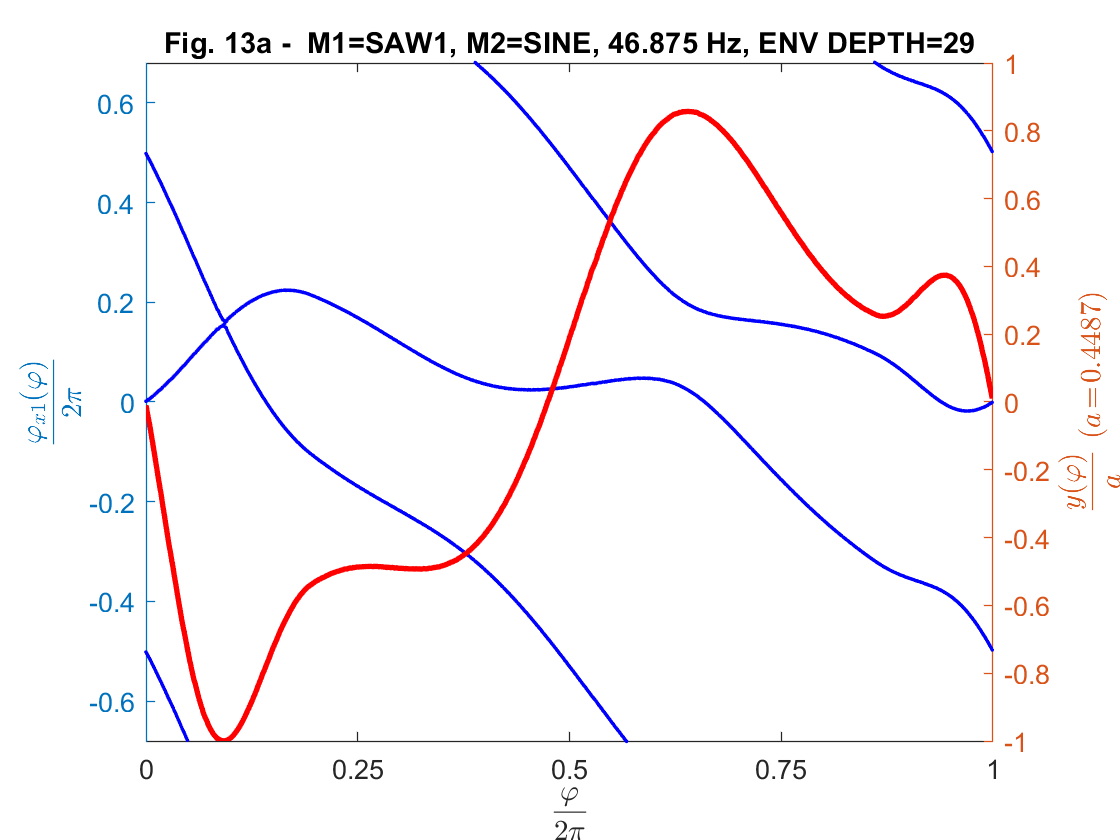

M1=SAW2, M2=SINE, 46.875 Hz, ENV DEPTH=29
vVZtools.loadRecording(rid="recordings/phaseModulationAnalysis/M1=SAW2, M2=SINE, 46.875 Hz, ENV DEPTH=29")
- Read wave file "../waves/recordings/phaseModulationAnalysis/M1=SAW2, M2=SINE, 46.875 Hz, ENV DEPTH=29.wav"
  - OK, 82260 samples
- Read annotation file "../labels/recordings/phaseModulationAnalysis/M1=SAW2, M2=SINE, 46.875 Hz, ENV DEPTH=29.par"
  - Read properties
    - OK, 14 properties
  - Read pitch marks
    - OK, 47 pitch marks
- Cycle data
    name: 'M1=SAW2, M2=SINE, 46.875 Hz, ENV DEPTH=29'
    wave: [1024×1 double]
      k0: 24886
       K: 1024
       a: 0.4802
       h: 0.2900



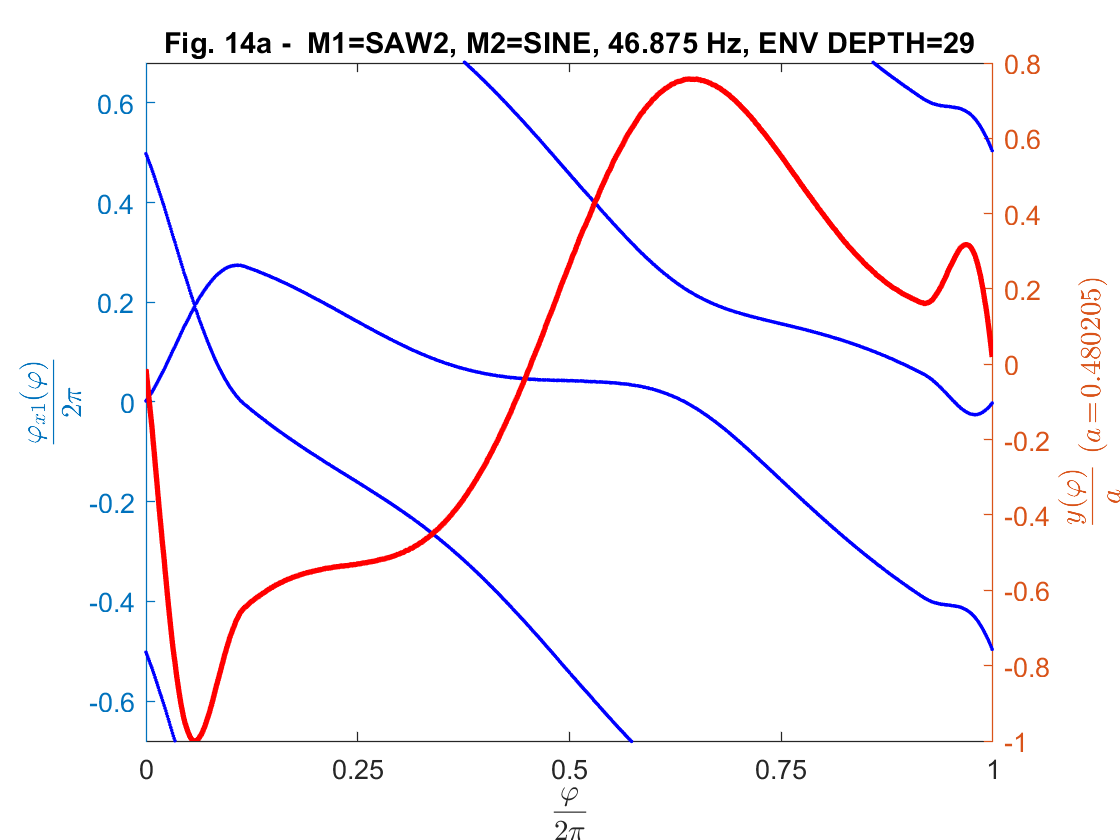

M1=SAW3, M2=SINE, 46.875 Hz, ENV DEPTH=29
vVZtools.loadRecording(rid="recordings/phaseModulationAnalysis/M1=SAW3, M2=SINE, 46.875 Hz, ENV DEPTH=29")
- Read wave file "../waves/recordings/phaseModulationAnalysis/M1=SAW3, M2=SINE, 46.875 Hz, ENV DEPTH=29.wav"
  - OK, 79260 samples
- Read annotation file "../labels/recordings/phaseModulationAnalysis/M1=SAW3, M2=SINE, 46.875 Hz, ENV DEPTH=29.par"
  - Read properties
    - OK, 14 properties
  - Read pitch marks
    - OK, 49 pitch marks
- Cycle data
    name: 'M1=SAW3, M2=SINE, 46.875 Hz, ENV DEPTH=29'
    wave: [1024×1 double]
      k0: 23876
       K: 1024
       a: 0.5037
       h: 0.2900



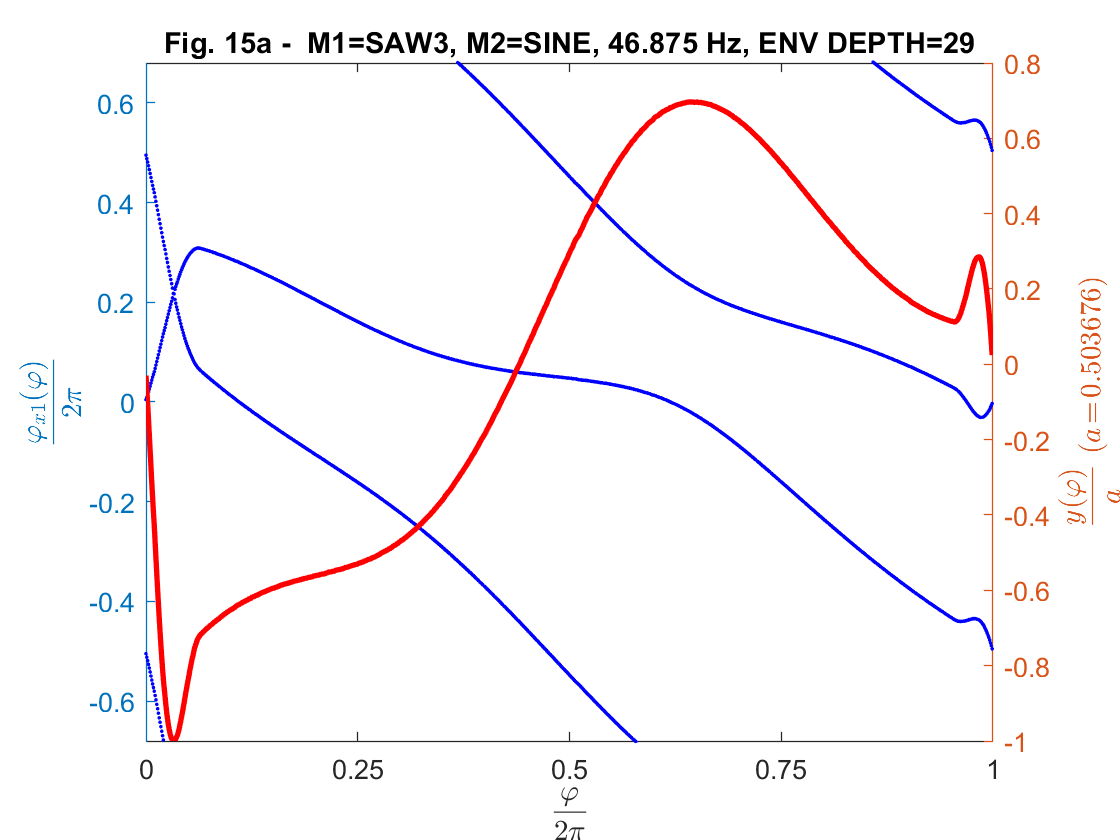

M1=SAW4, M2=SINE, 46.875 Hz, ENV DEPTH=29
vVZtools.loadRecording(rid="recordings/phaseModulationAnalysis/M1=SAW4, M2=SINE, 46.875 Hz, ENV DEPTH=29")
- Read wave file "../waves/recordings/phaseModulationAnalysis/M1=SAW4, M2=SINE, 46.875 Hz, ENV DEPTH=29.wav"
  - OK, 74760 samples
- Read annotation file "../labels/recordings/phaseModulationAnalysis/M1=SAW4, M2=SINE, 46.875 Hz, ENV DEPTH=29.par"
  - Read properties
    - OK, 14 properties
  - Read pitch marks
    - OK, 46 pitch marks
- Cycle data
    name: 'M1=SAW4, M2=SINE, 46.875 Hz, ENV DEPTH=29'
    wave: [1024×1 double]
      k0: 22790
       K: 1024
       a: 0.5184
       h: 0.2900



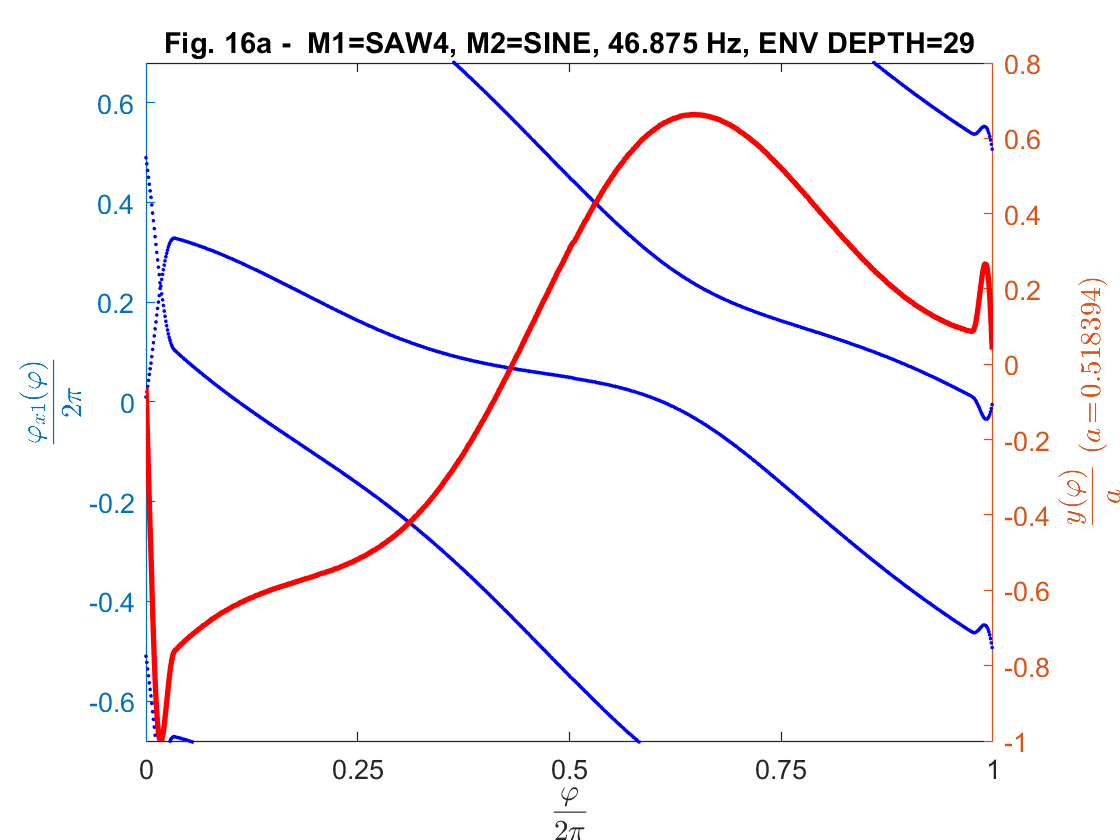

M1=SAW5, M2=SINE, 46.875 Hz, ENV DEPTH=29
vVZtools.loadRecording(rid="recordings/phaseModulationAnalysis/M1=SAW5, M2=SINE, 46.875 Hz, ENV DEPTH=29")
- Read wave file "../waves/recordings/phaseModulationAnalysis/M1=SAW5, M2=SINE, 46.875 Hz, ENV DEPTH=29.wav"
  - OK, 91260 samples
- Read annotation file "../labels/recordings/phaseModulationAnalysis/M1=SAW5, M2=SINE, 46.875 Hz, ENV DEPTH=29.par"
  - Read properties
    - OK, 14 properties
  - Read pitch marks
    - OK, 61 pitch marks
- Cycle data
    name: 'M1=SAW5, M2=SINE, 46.875 Hz, ENV DEPTH=29'
    wave: [1024×1 double]
      k0: 19875
       K: 1024
       a: 0.5259
       h: 0.2900



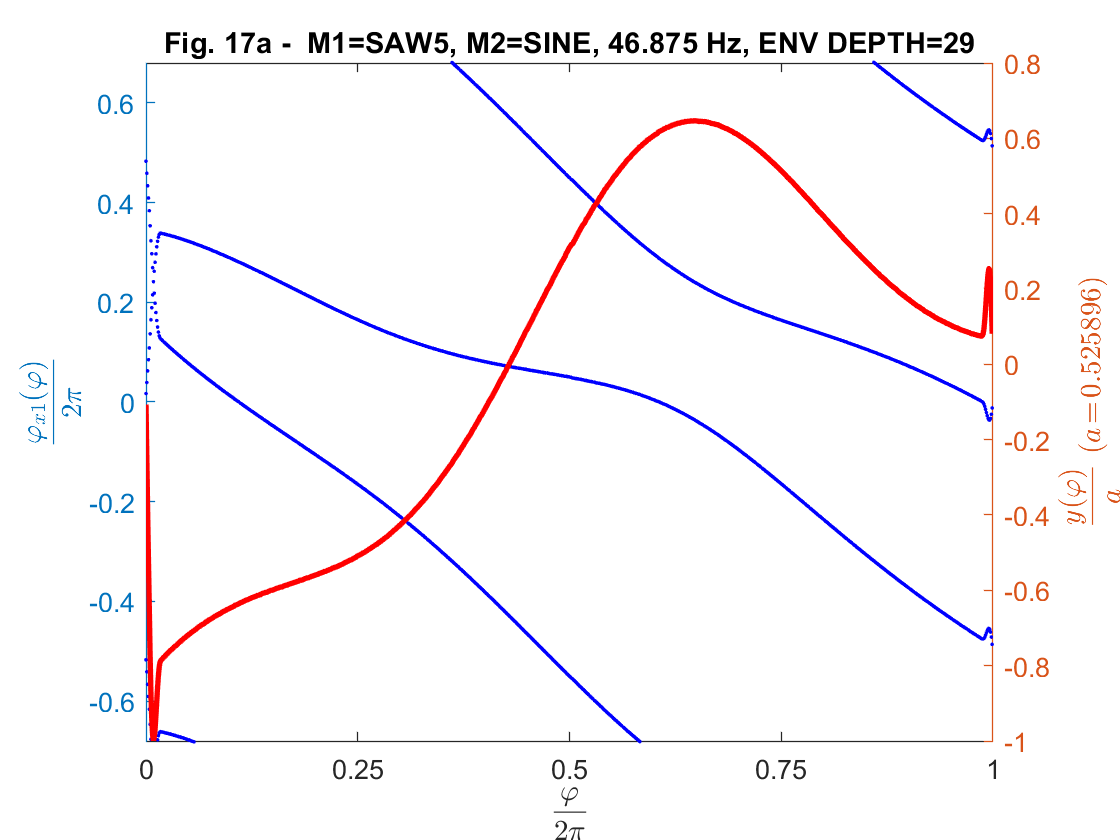

rlst = vVZtools.listRecordings([pfx '.*M1=SAW., M2=SINE.*']);
rec2 = cell(0);
for i=1:length(rlst)
  rec   = loadRecordings(rlst(i),1024); fprintf('- Cycle data\n'); disp(rec);
  k     = 0:rec.K-1;
  y     = rec.wave/rec.a;
  x2    = sin(2*pi.*k/rec.K-pi); % The carrier signal to be modulated
  phix1 = vVZtools.pmInvert(y,x2);
  ft    = sprintf('Fig. %da -  %s',FF+i-1,rec.name);
  yl    = [-2*rec.h-0.1 2*rec.h+0.1];
  plotPmInvert(y,phix1,[],ft,yl,rec.a);
  rec.phix1 = phix1;
  rec2{i} = rec;
end

### 2.4   `SAWn(SAWn)` Phase Modulation

**[TODO:** ...**]**

## 3   Conclusion

**[TODO:** ...**]**

Tuned into:

- Sandra: Paintings in Yellow

- Depeche Mode: Playing the Angel

## **Appendix A   Local Functions**

### **A.1   Load and Cut Recordings**

function rec = loadRecordings(rlst,K0)
  rec = struct([]);
  for i=1:length(rlst)
    pfx = [ fileparts(rlst{i}) '/' ];
    rec(i).name = strrep(rlst{i},pfx,'');
    fprintf('%s\n',rec(i).name);
    [wave,pm,props] = vVZtools.loadRecording(rlst{i});
    [rec(i).wave,rec(i).k0] = vVZtools.cutNiceCycle(wave,pm,[7 length(pm)-3],K0);
    rec(i).K    = length(rec(i).wave);
    x_mean      = mean(rec(i).wave);
    rec(i).wave = rec(i).wave - x_mean;   % Remove DC
    x_max       = max(rec(i).wave);
    x_min       = min(rec(i).wave);
    rec(i).a    = max(x_max,-x_min);
    rec(i).h    = vVZtools.parseKeyVal(props.value,'1-10.M1.ENV_DEPTH','%d');
    rec(i).h    = rec(i).h/100;
  end
end


### **A.2   Plot Inverted Phase Modulation**

function plotPmInvert(y,x1,x2,ft,yl,a)
  K = length(y);
  k = 0:K-1;
  figure;
  yyaxis right;
  if ~isempty(x2)
    plot(k,x2,'-','LineWidth',2,'Color',[1 0.8 0.8]); hold on;
  end
  plot(k,y ,'-','LineWidth',2,'Color','red'); hold on;
  title(ft);
  xlim([0 K]);
  set(gca,'XTick',0:K/4:K);
  set(gca,'XTickLabel',{'0','0.25','0.5','0.75','1'});
  xlabel('$$\frac{\varphi}{2\pi}$$','Interpreter','latex');
  ylabel("$$\frac{y(\varphi)}{a}$$ ($$a\!=\!"+sprintf('%g',a)+"$$)",'Interpreter','latex');
  yyaxis left;
  ylabel('$$\frac{\varphi_{x1}(\varphi)}{2\pi}$$','Interpreter','latex');
  ylim(yl);
  scatter(x1(1,:),x1(2,:),2,'filled','MarkerFaceColor','blue');
  hold off;
  drawnow;
end

### A.3   Plot Phase Modulation Model - Phase (=Modulating) Signal

function plotPmModelPhase(phix1_mea,phix1_mod,ft,yl,mX,mY)
  figure;
  K = length(phix1_mod);
  scatter(phix1_mea(1,:),phix1_mea(2,:),2,'filled','MarkerFaceColor',[0.85 0.85 1]);
  ylim(yl);
  xlim([0 K]);
  set(gca,'XTick',0:K/4:K);
  set(gca,'XTickLabel',{'0','0.25','0.5','0.75','1'});
  xlabel('$$\frac{\varphi}{2\pi}$$','Interpreter','latex');
  ylabel('$$\frac{\varphi_{x1}(\varphi)}{2\pi}$$','Interpreter','latex');
  title(ft);
  hold on;
  k = 0:K-1;
  plot(k,phix1_mod,'blue','LineWidth',2);
  scatter(mX,mY,100,'+','red');
  scatter(mX,mY,100,'o','red');
  hold off;
end

### A.4   Plot Phase Modulation Model - Modulated Signal

function plotPmModelSignal(y_mea,y_mod,ft)
  K = length(y_mea);
  k = 0:K-1;
  figure;
  yyaxis left;
  plot(k,y_mea,'LineWidth',2,'Color','blue');
  hold on;
  ylabel('$$y_{REC}(\varphi)$$','Interpreter','latex');
  yyaxis right;
  plot(k,y_mod,'LineWidth',2,'Color','red');
  ylabel("$$y_{MODEL}(\varphi)$$",'Interpreter','latex');
  title(ft);
  xlim([0,K]);
  set(gca,'XTick',0:K/4:K);
  set(gca,'XTickLabel',{'0','0.25','0.5','0.75','1'});
  xlabel('$$\frac{\varphi}{2\pi}$$','Interpreter','latex');
end